% make sure to add to environment the gp_mit package with SUBfolders
data = readtable('data_reduced.csv')

data = 328×47 table
    Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    matrixSTRENGTH    matrixStrainbreak    matrixImpact    impurityE    impuritySTRENGTH    impurityStrainbreak    impurityImpact    matrixXc    impurityXc    blendE    blendSTRENGTH    blendStrainbreak    blendImpact    MajorityPolymer_H

lables= data.Properties.VariableNames

lables = 1×47 cell array
    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'Matrix_viscosity'}    {'Contaminant_family'}    {'Contaminant_crystallinity'}    {'Contaminant_topology'}    {'Contaminant_SCB'}    {'Contaminant_LCB'}    {'Contaminant_viscosity'}    {'WeightImpurity'}    {'matrixE'}    {'matrixSTRENGTH'}    {'matrixStrainbreak'}    {'matrixImpact'}    {'impurityE'}    {'impuritySTRENGTH'}    {'impurityStrainbreak'}    {'impurityImpact'}    {'matrixXc'}    {'impurityXc'}    {'blendE'}    {'blendSTRENGTH'}    {'blendStrainbreak'}    {'blendImpact'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PA1'}    {'MajorityPolymer_PET1'}    {'MajorityPolymer_PP1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PP3'}    {'MajorityPolymer_PS1'}    {'MajorityPolymer_PS2'}    {'MinorityPolymer_HDPE1'}    {'MinorityPolymer_LDPE1'}    {'MinorityPolymer_LLDPE1'}    {'Min

lables = cell2table(lables);
lablesS = lables(1, 1:13);
lablesS2 = lables(1,28:end);
lablesE= [lablesS, lables(1,14), lables(1,18), lables(1,22:23), lablesS2];
lablesYE= lables(1,24);

12 features + %impurity

col 14 matrix E, 18 impurity E

col 22, 23 Matrix/imp XC

col 24 blendE

col 28 start of 1H (Majority and min polymers)

afetr preprocessing  (in XE ) there are only 5 vars non-discrete, and one is the percentage of mixture so that is already scaled to range between 0-1, 

14-17  will then just be divided by thir respective maxs and adjust to the scale. 

% skipping  Strenth Impact Strain Break
E =  table2array(data(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]))

E = 1.0e+03 *

         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0005    0.1924    0.9529    0.0327    0.0651    0.4624         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0002    0.1924    0.9529    0.0327    0.0651    0.2918         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0001    0.1924    0.9529    0.0327    0.0651    0.2380         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020  


% normalize to range 0-1 
Xe= [E(:,1:17), E(:,19:end)];
Ye = E(:,18)./max (E(:,18)); 
cols_continuous_norm = Xe(:,14:17) ./ max(Xe(:,14:17)); 
Xe(:,14:17)= cols_continuous_norm;


#### 10% test (secret) set, 90% for 10k CV

%creating 5 bins 
binEdgesI = linspace(min(Ye), max(Ye), 6)

binEdgesI =     0.0302    0.2242    0.4181    0.6121    0.8060    1.0000


% Get the bin indices for each instance
binIndicesI = discretize(Ye, binEdgesI)

binIndicesI =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


% Split the data into a training set and test set with stratification
cvI = cvpartition(binIndicesI, 'Holdout', 0.1)

cvI = Hold-out cross validation partition
   NumObservations: 328
       NumTestSets: 1
         TrainSize: 296
          TestSize: 32

%boolean vectors
trainingIndicesI = training(cvI);
secretIndices = test(cvI);

XT = Xe(trainingIndicesI,:);
Xsecret = Xe(secretIndices, :);
YT = Ye(trainingIndicesI);
Ysecret = Ye(secretIndices);

binEdgesT = linspace(min(YT), max(YT), 6)

binEdgesT =     0.0302    0.2242    0.4181    0.6121    0.8060    1.0000


binIndicesT = discretize(YT, binEdgesT)

binIndicesT =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


cv        = cvpartition(binIndicesT,'kfold',10);
numtestsets   = cv.NumTestSets;


meanfunc = [];    covfunc = @covSEiso;   likfunc = @likGauss; 
%initial param from documentation
hypSE = struct('mean', [] , 'cov', [1000; 15], 'lik', -1);
hypSE = minimize(hypSE, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain)

Function evaluation      0;  Value 6.732115e+01


hypSE = struct with fields:
    mean: []
     cov: [2×1 double]
     lik: -1.0061


%to find the intial hyp.cov train 10 times from XT 10% holdout cv, the minimazation is stoichastic
%so different results come 

%the hyp are given in [ln(cov(1)), ln(cov(2))]
hyp = exp(hypSE.cov(:))

hyp = 1.0e+06 *

       Inf
    3.2682


this initial CV is not understand the ranges to be tested for var and lengthscale. They both cannot tolerate smaller numbers than e(0.1) = 0.smth and variance has a limit to e^15 = 3.3* 10^6..  

%HYP are in LOG FORM; thus if hyp = 1000 it corresponds to log(1000) which
%is then passed as exp^100 = Inf thus 
%min range = 0.1 (e^0;1 = aprox 0) max range hyp=10; e^10 = 2*10^4 (already
%super big!)
lengthscales = linspace(0.1, 10, 4);
%var cannot surpass log(15) 
variances = linspace(0.1, 10, 4);
bestVar = 0;
bestL = 0;
bestMAPE = 300;
perf_l_var = zeros(length(lengthscales), length(variances));

% Create and open the log file
logFile = fopen('log.txt', 'w');

for i = 1:numel(lengthscales)
    for j = 1: numel(variances)
    hypSE.cov(1) = lengthscales(i);
    hypSE.cov(2) = variances(i);
    mapeVals = zeros(numtestsets, 1);
       for k = 1:numtestsets
        % Your existing code
        xtrain = XT(cv.training(k)); ytrain = YT(cv.training(k));
        xtest = XT(cv.test(k)); ytest = YT(cv.test(k));
        hypSE = minimize(hypSE, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain);
        [ymu ,ys2 ,fmu, fs2, lp] = gp(hypSE, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain, xtest);
        mape_val = calculateMAPE(ytest, ymu)
        mapeVals(k) = mape_val;
        % Log the length scale, variance, and MAPE for each iteration
        loggedLengthScale = hypSE.cov(1);
        loggedVariance = hypSE.cov(2);
        loggedMAPE = mape_val;

        % Write the logged values to the log file
        fprintf(logFile, 'Iteration lengthscale: %d\n', i);
        fprintf(logFile, 'Iteration variance: %d\n', j);
        fprintf(logFile, 'Length Scale: %.2f\n', loggedLengthScale);
        fprintf(logFile, 'Variance: %.2f\n', loggedVariance);
        fprintf(logFile, 'MAPE: %.2f\n', loggedMAPE);
        fprintf(logFile, '----------------------------\n');
       end
       perf_l_var(i,j) = mean(mapeVals) 
       if bestMAPE> mean(mapeVals)
           bestMAPE = mean(mapeVals);
           bestL = lengthscales(i);
           bestVar = variances(j);
       end
    end
    % Your existing code
end

Function evaluation      0;  Value -2.819977e+01
Function evaluation      6;  Value -5.836355e+01
Function evaluation      8;  Value -5.840963e+01
Function evaluation     10;  Value -5.855591e+01
Function evaluation     15;  Value -5.901053e+01
Function evaluation     18;  Value -5.901775e+01
Function evaluation     21;  Value -5.902017e+01
Function evaluation     24;  Value -5.902028e+01
Function evaluation     30;  Value -5.903124e+01
Function evaluation     33;  Value -5.903136e+01
Function evaluation     35;  Value -5.903173e+01
Function evaluation     38;  Value -5.903173e+01
Function evaluation     41;  Value -5.903173e+01
Function evaluation     43;  Value -5.903173e+01
Function evaluation     46;  Value -5.903173e+01
Function evaluation     50;  Value -5.903173e+01
Function evaluation     52;  Value -5.903173e+01
Function evaluation     56;  Value -5.903173e+01
Function evaluation     59;  Value -5.903173e+01
Function evaluation     63;  Value -5.903173e+01
Function evaluation 

mape_val = 105.5924

Function evaluation      0;  Value -6.243376e+01
Function evaluation      3;  Value -6.248548e+01
Function evaluation      5;  Value -6.248577e+01
Function evaluation      7;  Value -6.248580e+01
Function evaluation     10;  Value -6.248605e+01
Function evaluation     14;  Value -6.248605e+01
Function evaluation     19;  Value -6.248605e+01
Function evaluation     23;  Value -6.248605e+01
Function evaluation     26;  Value -6.248605e+01
Function evaluation     28;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     25;  Value -6.233873e+01
Function evaluation     27;  Value -6.233873e+01
Function evaluation     32;  Value -6.233873e+01
Function evaluation     36;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     21;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     54;  Value -5.945208e+01
Function evaluation     56;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8414

Function evaluation      0;  Value -5.755147e+01
Function evaluation      3;  Value -5.766066e+01
Function evaluation      5;  Value -5.766066e+01
Function evaluation     11;  Value -5.766088e+01
Function evaluation     15;  Value -5.766175e+01
Function evaluation     17;  Value -5.766178e+01
Function evaluation     18;  Value -5.766181e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     24;  Value -5.766181e+01
Function evaluation     26;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     55;  Value -6.020292e+01


mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     35;  Value -6.164787e+01
Function evaluation     38;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     44;  Value -6.164787e+01
Function evaluation     46;  Value -6.164787e+01
Function evaluation     50;  Value -6.164787e+01
Function evaluation     52;  Value -6.164787e+01
Function evaluation     56;  Value -6.164787e+01
Function evaluation     58;  Value -6.164787e+01
Function evaluation     61;  Value -6.164787e+01
Function evaluation     63;  Value -6.164787e+01
Function evaluation     67;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     24;  Value -5.987141e+01
Function evaluation     29;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -5.838042e+01
Function evaluation      4;  Value -5.838993e+01
Function evaluation     10;  Value -5.901032e+01
Function evaluation     13;  Value -5.901815e+01
Function evaluation     18;  Value -5.902568e+01
Function evaluation     21;  Value -5.902581e+01
Function evaluation     26;  Value -5.903150e+01
Function evaluation     30;  Value -5.903151e+01
Function evaluation     34;  Value -5.903163e+01
Function evaluation     37;  Value -5.903163e+01
Function evaluation     41;  Value -5.903165e+01
Function evaluation     44;  Value -5.903165e+01
Function evaluation     49;  Value -5.903168e+01
Function evaluation     52;  Value -5.903168e+01
Function evaluation     56;  Value -5.903171e+01
Function evaluation     59;  Value -5.903171e+01
Function evaluation     62;  Value -5.903172e+01
Function evaluation     65;  Value -5.903172e+01
Function evaluation     69;  Value -5.903173e+01
Function evaluation     72;  Value -5.903173e+01
Function evaluation 

mape_val = 105.5924

Function evaluation      0;  Value -6.243377e+01
Function evaluation      3;  Value -6.248548e+01
Function evaluation      5;  Value -6.248577e+01
Function evaluation      7;  Value -6.248580e+01
Function evaluation     10;  Value -6.248605e+01
Function evaluation     14;  Value -6.248605e+01
Function evaluation     19;  Value -6.248605e+01
Function evaluation     23;  Value -6.248605e+01
Function evaluation     26;  Value -6.248605e+01
Function evaluation     28;  Value -6.248605e+01
Function evaluation     34;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     24;  Value -6.233873e+01
Function evaluation     26;  Value -6.233873e+01
Function evaluation     31;  Value -6.233873e+01
Function evaluation     34;  Value -6.233873e+01
Function evaluation     39;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     21;  Value -6.307146e+01
Function evaluation     26;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     54;  Value -5.945208e+01
Function evaluation     56;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296742e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296743e+01
Function evaluation 

mape_val = 76.8415

Function evaluation      0;  Value -5.755155e+01
Function evaluation      3;  Value -5.766073e+01
Function evaluation      6;  Value -5.766073e+01
Function evaluation     14;  Value -5.766093e+01
Function evaluation     18;  Value -5.766175e+01
Function evaluation     20;  Value -5.766178e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     24;  Value -5.766181e+01
Function evaluation     29;  Value -5.766181e+01
Function evaluation     32;  Value -5.766181e+01
Function evaluation     37;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     54;  Value -6.020292e+01
Function evaluation     56;  Value -6.020292e+01
Function evaluation     59;  Value -6.020292e+01
Function evaluation     63;  Value -6.020292e+01


mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     35;  Value -6.164787e+01
Function evaluation     38;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     47;  Value -6.164787e+01
Function evaluation     51;  Value -6.164787e+01
Function evaluation     53;  Value -6.164787e+01
Function evaluation     56;  Value -6.164787e+01
Function evaluation     59;  Value -6.164787e+01
Function evaluation     64;  Value -6.164787e+01


mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     29;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9361         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -5.838042e+01
Function evaluation      4;  Value -5.838993e+01
Function evaluation     10;  Value -5.901032e+01
Function evaluation     13;  Value -5.901815e+01
Function evaluation     18;  Value -5.902568e+01
Function evaluation     21;  Value -5.902581e+01
Function evaluation     26;  Value -5.903150e+01
Function evaluation     30;  Value -5.903151e+01
Function evaluation     34;  Value -5.903163e+01
Function evaluation     37;  Value -5.903163e+01
Function evaluation     41;  Value -5.903165e+01
Function evaluation     44;  Value -5.903165e+01
Function evaluation     49;  Value -5.903168e+01
Function evaluation     52;  Value -5.903168e+01
Function evaluation     56;  Value -5.903171e+01
Function evaluation     59;  Value -5.903171e+01
Function evaluation     62;  Value -5.903172e+01
Function evaluation     65;  Value -5.903172e+01
Function evaluation     69;  Value -5.903173e+01
Function evaluation     72;  Value -5.903173e+01
Function evaluation 

mape_val = 105.5924

Function evaluation      0;  Value -6.243376e+01
Function evaluation      3;  Value -6.248548e+01
Function evaluation      5;  Value -6.248577e+01
Function evaluation      7;  Value -6.248580e+01
Function evaluation     10;  Value -6.248605e+01
Function evaluation     14;  Value -6.248605e+01
Function evaluation     19;  Value -6.248605e+01
Function evaluation     23;  Value -6.248605e+01
Function evaluation     26;  Value -6.248605e+01
Function evaluation     28;  Value -6.248605e+01
Function evaluation     33;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     25;  Value -6.233873e+01
Function evaluation     27;  Value -6.233873e+01
Function evaluation     31;  Value -6.233873e+01
Function evaluation     33;  Value -6.233873e+01
Function evaluation     38;  Value -6.233873e+01
Function evaluation     40;  Value -6.233873e+01
Function evaluation     46;  Value -6.233873e+01
Function evaluation     48;  Value -6.233873e+01
Function evaluation     56;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     21;  Value -6.307146e+01
Function evaluation     27;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     57;  Value -5.945208e+01
Function evaluation     59;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8415

Function evaluation      0;  Value -5.755157e+01
Function evaluation      3;  Value -5.766060e+01
Function evaluation      5;  Value -5.766061e+01
Function evaluation     10;  Value -5.766086e+01
Function evaluation     14;  Value -5.766176e+01
Function evaluation     16;  Value -5.766178e+01
Function evaluation     18;  Value -5.766181e+01
Function evaluation     20;  Value -5.766181e+01
Function evaluation     22;  Value -5.766181e+01
Function evaluation     24;  Value -5.766181e+01
Function evaluation     26;  Value -5.766181e+01
Function evaluation     28;  Value -5.766181e+01
Function evaluation     29;  Value -5.766181e+01
Function evaluation     31;  Value -5.766181e+01
Function evaluation     32;  Value -5.766181e+01
Function evaluation     33;  Value -5.766181e+01
Function evaluation     36;  Value -5.766181e+01
Function evaluation     39;  Value -5.766181e+01
Function evaluation     43;  Value -5.766181e+01
Function evaluation     45;  Value -5.766181e+01
Function evaluation 

mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     55;  Value -6.020292e+01
Function evaluation     57;  Value -6.020292e+01
Function evaluation     59;  Value -6.020292e+01
Function evaluation     82;  Value -6.020292e+01
Function evaluation     86;  Value -6.020292e+01


mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     35;  Value -6.164787e+01
Function evaluation     38;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     48;  Value -6.164787e+01
Function evaluation     53;  Value -6.164787e+01
Function evaluation     55;  Value -6.164787e+01


mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     29;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9361  114.9361         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -5.838042e+01
Function evaluation      4;  Value -5.838993e+01
Function evaluation     10;  Value -5.901032e+01
Function evaluation     13;  Value -5.901815e+01
Function evaluation     18;  Value -5.902568e+01
Function evaluation     21;  Value -5.902581e+01
Function evaluation     26;  Value -5.903150e+01
Function evaluation     30;  Value -5.903151e+01
Function evaluation     34;  Value -5.903163e+01
Function evaluation     37;  Value -5.903163e+01
Function evaluation     41;  Value -5.903165e+01
Function evaluation     44;  Value -5.903165e+01
Function evaluation     49;  Value -5.903168e+01
Function evaluation     52;  Value -5.903168e+01
Function evaluation     56;  Value -5.903171e+01
Function evaluation     59;  Value -5.903171e+01
Function evaluation     62;  Value -5.903172e+01
Function evaluation     65;  Value -5.903172e+01
Function evaluation     69;  Value -5.903173e+01
Function evaluation     72;  Value -5.903173e+01
Function evaluation 

mape_val = 105.5924

Function evaluation      0;  Value -6.243377e+01
Function evaluation      3;  Value -6.248548e+01
Function evaluation      5;  Value -6.248577e+01
Function evaluation      7;  Value -6.248580e+01
Function evaluation     10;  Value -6.248605e+01
Function evaluation     14;  Value -6.248605e+01
Function evaluation     19;  Value -6.248605e+01
Function evaluation     23;  Value -6.248605e+01
Function evaluation     26;  Value -6.248605e+01
Function evaluation     28;  Value -6.248605e+01
Function evaluation     31;  Value -6.248605e+01
Function evaluation     33;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     24;  Value -6.233873e+01
Function evaluation     26;  Value -6.233873e+01
Function evaluation     28;  Value -6.233873e+01
Function evaluation     30;  Value -6.233873e+01
Function evaluation     34;  Value -6.233873e+01
Function evaluation     36;  Value -6.233873e+01
Function evaluation     38;  Value -6.233873e+01
Function evaluation     43;  Value -6.233873e+01
Function evaluation     48;  Value -6.233873e+01
Function evaluation     50;  Value -6.233873e+01
Function evaluation     58;  Value -6.233873e+01
Function evaluation     60;  Value -6.233873e+01
Function evaluation     66;  Value -6.233873e+01
Function evaluation 

mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     20;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     47;  Value -5.945208e+01
Function evaluation     50;  Value -5.945208e+01
Function evaluation     55;  Value -5.945208e+01
Function evaluation     58;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8417

Function evaluation      0;  Value -5.755168e+01
Function evaluation      3;  Value -5.766071e+01
Function evaluation      5;  Value -5.766071e+01
Function evaluation     11;  Value -5.766092e+01
Function evaluation     15;  Value -5.766177e+01
Function evaluation     17;  Value -5.766179e+01
Function evaluation     19;  Value -5.766181e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     23;  Value -5.766181e+01
Function evaluation     25;  Value -5.766181e+01
Function evaluation     27;  Value -5.766181e+01
Function evaluation     29;  Value -5.766181e+01
Function evaluation     31;  Value -5.766181e+01
Function evaluation     33;  Value -5.766181e+01
Function evaluation     34;  Value -5.766181e+01
Function evaluation     36;  Value -5.766181e+01
Function evaluation     37;  Value -5.766181e+01
Function evaluation     39;  Value -5.766181e+01
Function evaluation     41;  Value -5.766181e+01
Function evaluation     42;  Value -5.766181e+01
Function evaluation 

mape_val = 97.9445

Function evaluation      0;  Value -6.018292e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     55;  Value -6.020292e+01
Function evaluation     58;  Value -6.020292e+01
Function evaluation     64;  Value -6.020292e+01
Function evaluation     68;  Value -6.020292e+01


mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     36;  Value -6.164787e+01
Function evaluation     39;  Value -6.164787e+01
Function evaluation     42;  Value -6.164787e+01
Function evaluation     43;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     48;  Value -6.164787e+01
Function evaluation     50;  Value -6.164787e+01
Function evaluation     53;  Value -6.164787e+01
Function evaluation     55;  Value -6.164787e+01
Function evaluation     59;  Value -6.164787e+01
Function evaluation     61;  Value -6.164787e+01
Function evaluation     64;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     29;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9361  114.9361  114.9361
         0         0         0         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -5.503884e+01
Function evaluation      4;  Value -5.505385e+01
Function evaluation     10;  Value -5.611272e+01
Function evaluation     13;  Value -5.612321e+01
Function evaluation     28;  Value -5.885921e+01
Function evaluation     32;  Value -5.886611e+01
Function evaluation     36;  Value -5.893015e+01
Function evaluation     39;  Value -5.893277e+01
Function evaluation     44;  Value -5.902975e+01
Function evaluation     47;  Value -5.903127e+01
Function evaluation     49;  Value -5.903165e+01
Function evaluation     51;  Value -5.903165e+01
Function evaluation     53;  Value -5.903165e+01
Function evaluation     55;  Value -5.903166e+01
Function evaluation     57;  Value -5.903166e+01
Function evaluation     60;  Value -5.903168e+01
Function evaluation     63;  Value -5.903168e+01
Function evaluation     65;  Value -5.903168e+01
Function evaluation     67;  Value -5.903168e+01
Function evaluation     69;  Value -5.903169e+01
Function evaluation 

mape_val = 105.5936

Function evaluation      0;  Value -6.243381e+01
Function evaluation      3;  Value -6.248554e+01
Function evaluation      5;  Value -6.248580e+01
Function evaluation      7;  Value -6.248583e+01
Function evaluation     10;  Value -6.248605e+01
Function evaluation     14;  Value -6.248605e+01
Function evaluation     19;  Value -6.248605e+01
Function evaluation     22;  Value -6.248605e+01
Function evaluation     26;  Value -6.248605e+01
Function evaluation     29;  Value -6.248605e+01
Function evaluation     32;  Value -6.248605e+01
Function evaluation     34;  Value -6.248605e+01
Function evaluation     36;  Value -6.248605e+01
Function evaluation     38;  Value -6.248605e+01
Function evaluation     41;  Value -6.248605e+01
Function evaluation     43;  Value -6.248605e+01
Function evaluation     46;  Value -6.248605e+01
Function evaluation     48;  Value -6.248605e+01
Function evaluation     51;  Value -6.248605e+01
Function evaluation     53;  Value -6.248605e+01
Function evaluation 

mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     25;  Value -6.233873e+01
Function evaluation     27;  Value -6.233873e+01
Function evaluation     32;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     24;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     47;  Value -5.945208e+01
Function evaluation     50;  Value -5.945208e+01
Function evaluation     55;  Value -5.945208e+01
Function evaluation     58;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8418

Function evaluation      0;  Value -5.755170e+01
Function evaluation      3;  Value -5.766071e+01
Function evaluation      5;  Value -5.766071e+01
Function evaluation     11;  Value -5.766092e+01
Function evaluation     15;  Value -5.766176e+01
Function evaluation     19;  Value -5.766177e+01
Function evaluation     24;  Value -5.766181e+01
Function evaluation     29;  Value -5.766181e+01
Function evaluation     33;  Value -5.766181e+01
Function evaluation     36;  Value -5.766181e+01
Function evaluation     41;  Value -5.766181e+01
Function evaluation     43;  Value -5.766181e+01
Function evaluation     46;  Value -5.766181e+01
Function evaluation     48;  Value -5.766181e+01
Function evaluation     49;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     55;  Value -6.020292e+01
Function evaluation     57;  Value -6.020292e+01
Function evaluation     61;  Value -6.020292e+01
Function evaluation     63;  Value -6.020292e+01
Function evaluation     67;  Value -6.020292e+01
Function evaluation 

mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     34;  Value -6.164787e+01
Function evaluation     37;  Value -6.164787e+01
Function evaluation     40;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     43;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     47;  Value -6.164787e+01
Function evaluation     51;  Value -6.164787e+01
Function evaluation     53;  Value -6.164787e+01
Function evaluation     56;  Value -6.164787e+01
Function evaluation     58;  Value -6.164787e+01
Function evaluation     61;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     16;  Value -5.987141e+01
Function evaluation     21;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     31;  Value -5.987141e+01
Function evaluation     33;  Value -5.987141e+01
Function evaluation     38;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9361  114.9361  114.9361
  114.9362         0         0         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -5.503884e+01
Function evaluation      4;  Value -5.505385e+01
Function evaluation     10;  Value -5.611272e+01
Function evaluation     13;  Value -5.612321e+01
Function evaluation     28;  Value -5.885922e+01
Function evaluation     32;  Value -5.886612e+01
Function evaluation     36;  Value -5.893014e+01
Function evaluation     39;  Value -5.893276e+01
Function evaluation     44;  Value -5.902973e+01
Function evaluation     47;  Value -5.903145e+01
Function evaluation     49;  Value -5.903164e+01
Function evaluation     51;  Value -5.903165e+01
Function evaluation     54;  Value -5.903165e+01
Function evaluation     57;  Value -5.903166e+01
Function evaluation     59;  Value -5.903166e+01
Function evaluation     62;  Value -5.903166e+01
Function evaluation     64;  Value -5.903166e+01
Function evaluation     67;  Value -5.903167e+01
Function evaluation     69;  Value -5.903167e+01
Function evaluation     72;  Value -5.903168e+01
Function evaluation 

mape_val = 105.5939

Function evaluation      0;  Value -6.243389e+01
Function evaluation      3;  Value -6.248548e+01
Function evaluation      6;  Value -6.248578e+01
Function evaluation      8;  Value -6.248582e+01
Function evaluation     11;  Value -6.248605e+01
Function evaluation     15;  Value -6.248605e+01
Function evaluation     20;  Value -6.248605e+01
Function evaluation     23;  Value -6.248605e+01
Function evaluation     26;  Value -6.248605e+01
Function evaluation     29;  Value -6.248605e+01
Function evaluation     33;  Value -6.248605e+01
Function evaluation     36;  Value -6.248605e+01
Function evaluation     40;  Value -6.248605e+01
Function evaluation     43;  Value -6.248605e+01
Function evaluation     47;  Value -6.248605e+01
Function evaluation     50;  Value -6.248605e+01
Function evaluation     55;  Value -6.248605e+01
Function evaluation     61;  Value -6.248605e+01
Function evaluation     69;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     23;  Value -6.233873e+01
Function evaluation     25;  Value -6.233873e+01
Function evaluation     27;  Value -6.233873e+01
Function evaluation     29;  Value -6.233873e+01
Function evaluation     32;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     21;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     55;  Value -5.945208e+01
Function evaluation     60;  Value -5.945208e+01


mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8414

Function evaluation      0;  Value -5.755149e+01
Function evaluation      3;  Value -5.766066e+01
Function evaluation      5;  Value -5.766066e+01
Function evaluation     11;  Value -5.766089e+01
Function evaluation     15;  Value -5.766175e+01
Function evaluation     17;  Value -5.766178e+01
Function evaluation     18;  Value -5.766181e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     27;  Value -5.766181e+01
Function evaluation     30;  Value -5.766181e+01
Function evaluation     33;  Value -5.766181e+01
Function evaluation     36;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     55;  Value -6.020292e+01
Function evaluation     57;  Value -6.020292e+01
Function evaluation     59;  Value -6.020292e+01


mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     34;  Value -6.164787e+01
Function evaluation     37;  Value -6.164787e+01
Function evaluation     40;  Value -6.164787e+01
Function evaluation     43;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     48;  Value -6.164787e+01
Function evaluation     50;  Value -6.164787e+01
Function evaluation     54;  Value -6.164787e+01
Function evaluation     57;  Value -6.164787e+01
Function evaluation     61;  Value -6.164787e+01
Function evaluation     64;  Value -6.164787e+01
Function evaluation     67;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     16;  Value -5.987141e+01
Function evaluation     22;  Value -5.987141e+01
Function evaluation     26;  Value -5.987141e+01
Function evaluation     30;  Value -5.987141e+01
Function evaluation     32;  Value -5.987141e+01
Function evaluation     35;  Value -5.987141e+01
Function evaluation     38;  Value -5.987141e+01
Function evaluation     40;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9361  114.9361  114.9361
  114.9362  114.9362         0         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -5.503884e+01
Function evaluation      4;  Value -5.505385e+01
Function evaluation     10;  Value -5.611272e+01
Function evaluation     13;  Value -5.612321e+01
Function evaluation     28;  Value -5.885921e+01
Function evaluation     32;  Value -5.886611e+01
Function evaluation     36;  Value -5.893015e+01
Function evaluation     39;  Value -5.893277e+01
Function evaluation     44;  Value -5.902975e+01
Function evaluation     47;  Value -5.903133e+01
Function evaluation     49;  Value -5.903165e+01
Function evaluation     51;  Value -5.903165e+01
Function evaluation     54;  Value -5.903165e+01
Function evaluation     56;  Value -5.903166e+01
Function evaluation     58;  Value -5.903166e+01
Function evaluation     60;  Value -5.903166e+01
Function evaluation     62;  Value -5.903166e+01
Function evaluation     64;  Value -5.903166e+01
Function evaluation     66;  Value -5.903166e+01
Function evaluation     68;  Value -5.903167e+01
Function evaluation 

mape_val = 105.5930

Function evaluation      0;  Value -6.243354e+01
Function evaluation      3;  Value -6.248555e+01
Function evaluation      5;  Value -6.248581e+01
Function evaluation      8;  Value -6.248583e+01
Function evaluation     12;  Value -6.248605e+01
Function evaluation     16;  Value -6.248605e+01
Function evaluation     21;  Value -6.248605e+01
Function evaluation     24;  Value -6.248605e+01
Function evaluation     27;  Value -6.248605e+01
Function evaluation     29;  Value -6.248605e+01
Function evaluation     32;  Value -6.248605e+01
Function evaluation     35;  Value -6.248605e+01
Function evaluation     40;  Value -6.248605e+01
Function evaluation     42;  Value -6.248605e+01
Function evaluation     44;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     23;  Value -6.233873e+01
Function evaluation     25;  Value -6.233873e+01
Function evaluation     26;  Value -6.233873e+01
Function evaluation     30;  Value -6.233873e+01
Function evaluation     34;  Value -6.233873e+01
Function evaluation     43;  Value -6.233873e+01
Function evaluation     47;  Value -6.233873e+01
Function evaluation     49;  Value -6.233873e+01
Function evaluation     53;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     21;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     56;  Value -5.945208e+01
Function evaluation     58;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296742e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296743e+01
Function evaluation     39;  Value -6.296743e+01
Function evaluation 

mape_val = 76.8417

Function evaluation      0;  Value -5.755160e+01
Function evaluation      3;  Value -5.766072e+01
Function evaluation      5;  Value -5.766072e+01
Function evaluation     12;  Value -5.766093e+01
Function evaluation     16;  Value -5.766177e+01
Function evaluation     18;  Value -5.766179e+01
Function evaluation     20;  Value -5.766181e+01
Function evaluation     22;  Value -5.766181e+01
Function evaluation     24;  Value -5.766181e+01
Function evaluation     26;  Value -5.766181e+01
Function evaluation     27;  Value -5.766181e+01
Function evaluation     29;  Value -5.766181e+01
Function evaluation     30;  Value -5.766181e+01
Function evaluation     32;  Value -5.766181e+01
Function evaluation     35;  Value -5.766181e+01
Function evaluation     37;  Value -5.766181e+01
Function evaluation     41;  Value -5.766181e+01
Function evaluation     43;  Value -5.766181e+01
Function evaluation     46;  Value -5.766181e+01
Function evaluation     49;  Value -5.766181e+01
Function evaluation 

mape_val = 97.9445

Function evaluation      0;  Value -6.018292e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     56;  Value -6.020292e+01
Function evaluation     58;  Value -6.020292e+01
Function evaluation     63;  Value -6.020292e+01


mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     35;  Value -6.164787e+01
Function evaluation     38;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     44;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     47;  Value -6.164787e+01
Function evaluation     49;  Value -6.164787e+01
Function evaluation     51;  Value -6.164787e+01
Function evaluation     53;  Value -6.164787e+01
Function evaluation     55;  Value -6.164787e+01
Function evaluation     57;  Value -6.164787e+01
Function evaluation     59;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     16;  Value -5.987141e+01
Function evaluation     22;  Value -5.987141e+01
Function evaluation     26;  Value -5.987141e+01
Function evaluation     30;  Value -5.987141e+01
Function evaluation     32;  Value -5.987141e+01
Function evaluation     36;  Value -5.987141e+01
Function evaluation     38;  Value -5.987141e+01
Function evaluation     41;  Value -5.987141e+01
Function evaluation     43;  Value -5.987141e+01
Function evaluation     46;  Value -5.987141e+01
Function evaluation     48;  Value -5.987141e+01
Function evaluation     50;  Value -5.987141e+01
Function evaluation     53;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9361  114.9361  114.9361
  114.9362  114.9362  114.9362         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -5.503884e+01
Function evaluation      4;  Value -5.505385e+01
Function evaluation     10;  Value -5.611272e+01
Function evaluation     13;  Value -5.612321e+01
Function evaluation     28;  Value -5.885921e+01
Function evaluation     32;  Value -5.886610e+01
Function evaluation     36;  Value -5.893015e+01
Function evaluation     39;  Value -5.893277e+01
Function evaluation     44;  Value -5.902976e+01
Function evaluation     47;  Value -5.903120e+01
Function evaluation     49;  Value -5.903165e+01
Function evaluation     51;  Value -5.903165e+01
Function evaluation     53;  Value -5.903165e+01
Function evaluation     55;  Value -5.903166e+01
Function evaluation     57;  Value -5.903166e+01
Function evaluation     59;  Value -5.903166e+01
Function evaluation     61;  Value -5.903166e+01
Function evaluation     63;  Value -5.903166e+01
Function evaluation     65;  Value -5.903166e+01
Function evaluation     67;  Value -5.903167e+01
Function evaluation 

mape_val = 105.5941

Function evaluation      0;  Value -6.243353e+01
Function evaluation      3;  Value -6.248547e+01
Function evaluation      5;  Value -6.248576e+01
Function evaluation      7;  Value -6.248579e+01
Function evaluation     10;  Value -6.248600e+01
Function evaluation     12;  Value -6.248605e+01
Function evaluation     14;  Value -6.248605e+01
Function evaluation     16;  Value -6.248605e+01
Function evaluation     19;  Value -6.248605e+01
Function evaluation     21;  Value -6.248605e+01
Function evaluation     24;  Value -6.248605e+01
Function evaluation     26;  Value -6.248605e+01
Function evaluation     29;  Value -6.248605e+01
Function evaluation     31;  Value -6.248605e+01
Function evaluation     34;  Value -6.248605e+01
Function evaluation     36;  Value -6.248605e+01
Function evaluation     39;  Value -6.248605e+01
Function evaluation     41;  Value -6.248605e+01
Function evaluation     44;  Value -6.248605e+01
Function evaluation     46;  Value -6.248605e+01
Function evaluation 

mape_val = 139.9585

Function evaluation      0;  Value -6.233859e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     24;  Value -6.233873e+01
Function evaluation     26;  Value -6.233873e+01
Function evaluation     29;  Value -6.233873e+01
Function evaluation     33;  Value -6.233873e+01
Function evaluation     36;  Value -6.233873e+01
Function evaluation     40;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     24;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     54;  Value -5.945208e+01
Function evaluation     57;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8414

Function evaluation      0;  Value -5.755147e+01
Function evaluation      3;  Value -5.766066e+01
Function evaluation      5;  Value -5.766066e+01
Function evaluation     11;  Value -5.766088e+01
Function evaluation     15;  Value -5.766175e+01
Function evaluation     17;  Value -5.766178e+01
Function evaluation     18;  Value -5.766181e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     25;  Value -5.766181e+01
Function evaluation     29;  Value -5.766181e+01
Function evaluation     34;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     54;  Value -6.020292e+01
Function evaluation     56;  Value -6.020292e+01
Function evaluation     58;  Value -6.020292e+01
Function evaluation     60;  Value -6.020292e+01
Function evaluation     63;  Value -6.020292e+01
Function evaluation 

mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     35;  Value -6.164787e+01
Function evaluation     38;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     47;  Value -6.164787e+01
Function evaluation     50;  Value -6.164787e+01
Function evaluation     52;  Value -6.164787e+01
Function evaluation     55;  Value -6.164787e+01
Function evaluation     57;  Value -6.164787e+01
Function evaluation     60;  Value -6.164787e+01
Function evaluation     62;  Value -6.164787e+01
Function evaluation     66;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     29;  Value -5.987141e+01
Function evaluation     33;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9361  114.9361  114.9361
  114.9362  114.9362  114.9362  114.9363
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -5.173874e+01
Function evaluation      4;  Value -5.175375e+01
Function evaluation     10;  Value -5.281323e+01
Function evaluation     13;  Value -5.282372e+01
Function evaluation     22;  Value -5.868653e+01
Function evaluation     26;  Value -5.871400e+01
Function evaluation     28;  Value -5.871579e+01
Function evaluation     31;  Value -5.871582e+01
Function evaluation     34;  Value -5.871582e+01
Function evaluation     37;  Value -5.871582e+01
Function evaluation     40;  Value -5.871582e+01
Function evaluation     42;  Value -5.871582e+01
Function evaluation     46;  Value -5.871582e+01
Function evaluation     48;  Value -5.871582e+01
Function evaluation     52;  Value -5.871582e+01
Function evaluation     54;  Value -5.871582e+01
Function evaluation     77;  Value -5.885088e+01
Function evaluation     81;  Value -5.893926e+01
Function evaluation     84;  Value -5.894215e+01
Function evaluation     88;  Value -5.897085e+01
Function evaluation 

mape_val = 105.5875

Function evaluation      0;  Value -6.243202e+01
Function evaluation      3;  Value -6.248484e+01
Function evaluation      5;  Value -6.248527e+01
Function evaluation      8;  Value -6.248530e+01
Function evaluation     12;  Value -6.248584e+01
Function evaluation     14;  Value -6.248593e+01
Function evaluation     16;  Value -6.248605e+01
Function evaluation     19;  Value -6.248605e+01
Function evaluation     22;  Value -6.248605e+01
Function evaluation     26;  Value -6.248605e+01
Function evaluation     29;  Value -6.248605e+01
Function evaluation     34;  Value -6.248605e+01
Function evaluation     38;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     24;  Value -6.233873e+01
Function evaluation     26;  Value -6.233873e+01
Function evaluation     30;  Value -6.233873e+01
Function evaluation     32;  Value -6.233873e+01
Function evaluation     36;  Value -6.233873e+01
Function evaluation     39;  Value -6.233873e+01
Function evaluation     45;  Value -6.233873e+01
Function evaluation     47;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     23;  Value -6.307146e+01
Function evaluation     29;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     47;  Value -5.945208e+01
Function evaluation     50;  Value -5.945208e+01
Function evaluation     55;  Value -5.945208e+01
Function evaluation     57;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8414

Function evaluation      0;  Value -5.755147e+01
Function evaluation      3;  Value -5.766066e+01
Function evaluation      5;  Value -5.766066e+01
Function evaluation     11;  Value -5.766088e+01
Function evaluation     15;  Value -5.766175e+01
Function evaluation     17;  Value -5.766178e+01
Function evaluation     18;  Value -5.766181e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     25;  Value -5.766181e+01
Function evaluation     28;  Value -5.766181e+01
Function evaluation     31;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     55;  Value -6.020292e+01
Function evaluation     57;  Value -6.020292e+01
Function evaluation     58;  Value -6.020292e+01
Function evaluation     60;  Value -6.020292e+01
Function evaluation     63;  Value -6.020292e+01
Function evaluation 

mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     35;  Value -6.164787e+01
Function evaluation     38;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     44;  Value -6.164787e+01
Function evaluation     46;  Value -6.164787e+01
Function evaluation     50;  Value -6.164787e+01
Function evaluation     52;  Value -6.164787e+01
Function evaluation     57;  Value -6.164787e+01
Function evaluation     59;  Value -6.164787e+01
Function evaluation     63;  Value -6.164787e+01
Function evaluation     66;  Value -6.164787e+01
Function evaluation     71;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     29;  Value -5.987141e+01
Function evaluation     33;  Value -5.987141e+01
Function evaluation     38;  Value -5.987141e+01
Function evaluation     44;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9361  114.9361  114.9361
  114.9362  114.9362  114.9362  114.9363
  114.9356         0         0         0
         0         0         0         0


Function evaluation      0;  Value -5.173874e+01
Function evaluation      4;  Value -5.175375e+01
Function evaluation     10;  Value -5.281323e+01
Function evaluation     13;  Value -5.282372e+01
Function evaluation     22;  Value -5.868687e+01
Function evaluation     26;  Value -5.871408e+01
Function evaluation     28;  Value -5.871579e+01
Function evaluation     31;  Value -5.871582e+01
Function evaluation     34;  Value -5.871582e+01
Function evaluation     37;  Value -5.871582e+01
Function evaluation     40;  Value -5.871582e+01
Function evaluation     42;  Value -5.871582e+01
Function evaluation     47;  Value -5.871582e+01
Function evaluation     49;  Value -5.871582e+01
Function evaluation     54;  Value -5.871582e+01
Function evaluation     56;  Value -5.871582e+01
Function evaluation     80;  Value -5.883336e+01
Function evaluation     86;  Value -5.902669e+01
Function evaluation     90;  Value -5.902681e+01
Function evaluation     94;  Value -5.903040e+01
Function evaluation 

mape_val = 105.5829

Function evaluation      0;  Value -6.243337e+01
Function evaluation      3;  Value -6.248527e+01
Function evaluation      5;  Value -6.248546e+01
Function evaluation      8;  Value -6.248547e+01
Function evaluation     13;  Value -6.248582e+01
Function evaluation     15;  Value -6.248605e+01
Function evaluation     20;  Value -6.248605e+01
Function evaluation     24;  Value -6.248605e+01
Function evaluation     27;  Value -6.248605e+01
Function evaluation     32;  Value -6.248605e+01
Function evaluation     34;  Value -6.248605e+01
Function evaluation     39;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     24;  Value -6.233873e+01
Function evaluation     26;  Value -6.233873e+01
Function evaluation     29;  Value -6.233873e+01
Function evaluation     31;  Value -6.233873e+01
Function evaluation     35;  Value -6.233873e+01
Function evaluation     37;  Value -6.233873e+01
Function evaluation     42;  Value -6.233873e+01
Function evaluation     45;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     20;  Value -6.307146e+01
Function evaluation     30;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     47;  Value -5.945208e+01
Function evaluation     50;  Value -5.945208e+01
Function evaluation     55;  Value -5.945208e+01


mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296743e+01
Function evaluation 

mape_val = 76.8413

Function evaluation      0;  Value -5.755145e+01
Function evaluation      3;  Value -5.766067e+01
Function evaluation      5;  Value -5.766067e+01
Function evaluation     12;  Value -5.766088e+01
Function evaluation     16;  Value -5.766173e+01
Function evaluation     18;  Value -5.766178e+01
Function evaluation     20;  Value -5.766181e+01
Function evaluation     22;  Value -5.766181e+01
Function evaluation     24;  Value -5.766181e+01
Function evaluation     25;  Value -5.766181e+01
Function evaluation     27;  Value -5.766181e+01
Function evaluation     29;  Value -5.766181e+01
Function evaluation     31;  Value -5.766181e+01
Function evaluation     33;  Value -5.766181e+01
Function evaluation     35;  Value -5.766181e+01
Function evaluation     37;  Value -5.766181e+01
Function evaluation     39;  Value -5.766181e+01
Function evaluation     41;  Value -5.766181e+01
Function evaluation     44;  Value -5.766181e+01
Function evaluation     45;  Value -5.766181e+01
Function evaluation 

mape_val = 97.9445

Function evaluation      0;  Value -6.018292e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     56;  Value -6.020292e+01
Function evaluation     58;  Value -6.020292e+01
Function evaluation     63;  Value -6.020292e+01
Function evaluation     66;  Value -6.020292e+01
Function evaluation     71;  Value -6.020292e+01
Function evaluation 

mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     35;  Value -6.164787e+01
Function evaluation     38;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     47;  Value -6.164787e+01
Function evaluation     51;  Value -6.164787e+01
Function evaluation     53;  Value -6.164787e+01
Function evaluation     57;  Value -6.164787e+01
Function evaluation     59;  Value -6.164787e+01
Function evaluation     62;  Value -6.164787e+01


mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     26;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9361  114.9361  114.9361
  114.9362  114.9362  114.9362  114.9363
  114.9356  114.9351         0         0
         0         0         0         0


Function evaluation      0;  Value -5.173874e+01
Function evaluation      4;  Value -5.175375e+01
Function evaluation     10;  Value -5.281321e+01
Function evaluation     13;  Value -5.282372e+01
Function evaluation     22;  Value -5.868751e+01
Function evaluation     26;  Value -5.871422e+01
Function evaluation     28;  Value -5.871580e+01
Function evaluation     31;  Value -5.871582e+01
Function evaluation     34;  Value -5.871582e+01
Function evaluation     37;  Value -5.871582e+01
Function evaluation     41;  Value -5.871582e+01
Function evaluation     43;  Value -5.871582e+01
Function evaluation     48;  Value -5.871582e+01
Function evaluation     50;  Value -5.871582e+01
Function evaluation     56;  Value -5.871583e+01
Function evaluation     58;  Value -5.871583e+01
Function evaluation     80;  Value -5.894647e+01
Function evaluation     83;  Value -5.898829e+01
Function evaluation     84;  Value -5.902379e+01
Function evaluation     86;  Value -5.902411e+01
Function evaluation 

mape_val = 105.5736

Function evaluation      0;  Value -6.243283e+01
Function evaluation      3;  Value -6.248390e+01
Function evaluation      6;  Value -6.248452e+01
Function evaluation      8;  Value -6.248473e+01
Function evaluation     12;  Value -6.248535e+01
Function evaluation     13;  Value -6.248601e+01
Function evaluation     16;  Value -6.248604e+01
Function evaluation     18;  Value -6.248605e+01
Function evaluation     20;  Value -6.248605e+01
Function evaluation     24;  Value -6.248605e+01
Function evaluation     27;  Value -6.248605e+01
Function evaluation     32;  Value -6.248605e+01
Function evaluation     36;  Value -6.248605e+01
Function evaluation     41;  Value -6.248605e+01
Function evaluation     45;  Value -6.248605e+01
Function evaluation     50;  Value -6.248605e+01
Function evaluation     63;  Value -6.248605e+01
Function evaluation     69;  Value -6.248605e+01
Function evaluation     71;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     24;  Value -6.233873e+01
Function evaluation     26;  Value -6.233873e+01
Function evaluation     32;  Value -6.233873e+01
Function evaluation     35;  Value -6.233873e+01
Function evaluation     39;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     24;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     54;  Value -5.945208e+01
Function evaluation     58;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8417

Function evaluation      0;  Value -5.755146e+01
Function evaluation      3;  Value -5.766070e+01
Function evaluation      5;  Value -5.766070e+01
Function evaluation     11;  Value -5.766092e+01
Function evaluation     15;  Value -5.766176e+01
Function evaluation     17;  Value -5.766178e+01
Function evaluation     19;  Value -5.766181e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     23;  Value -5.766181e+01
Function evaluation     25;  Value -5.766181e+01
Function evaluation     26;  Value -5.766181e+01
Function evaluation     28;  Value -5.766181e+01
Function evaluation     29;  Value -5.766181e+01
Function evaluation     31;  Value -5.766181e+01
Function evaluation     34;  Value -5.766181e+01
Function evaluation     36;  Value -5.766181e+01
Function evaluation     40;  Value -5.766181e+01
Function evaluation     42;  Value -5.766181e+01
Function evaluation     45;  Value -5.766181e+01
Function evaluation     47;  Value -5.766181e+01
Function evaluation 

mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     49;  Value -6.020292e+01
Function evaluation     51;  Value -6.020292e+01
Function evaluation     55;  Value -6.020292e+01
Function evaluation     57;  Value -6.020292e+01
Function evaluation     61;  Value -6.020292e+01
Function evaluation     63;  Value -6.020292e+01
Function evaluation     67;  Value -6.020292e+01


mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     35;  Value -6.164787e+01
Function evaluation     38;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     44;  Value -6.164787e+01
Function evaluation     46;  Value -6.164787e+01
Function evaluation     50;  Value -6.164787e+01
Function evaluation     52;  Value -6.164787e+01
Function evaluation     56;  Value -6.164787e+01
Function evaluation     58;  Value -6.164787e+01
Function evaluation     61;  Value -6.164787e+01
Function evaluation     63;  Value -6.164787e+01
Function evaluation     66;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9361  114.9361  114.9361
  114.9362  114.9362  114.9362  114.9363
  114.9356  114.9351  114.9342         0
         0         0         0         0


Function evaluation      0;  Value -5.173874e+01
Function evaluation      4;  Value -5.175375e+01
Function evaluation     10;  Value -5.281323e+01
Function evaluation     13;  Value -5.282372e+01
Function evaluation     22;  Value -5.868678e+01
Function evaluation     26;  Value -5.871406e+01
Function evaluation     28;  Value -5.871579e+01
Function evaluation     31;  Value -5.871582e+01
Function evaluation     34;  Value -5.871582e+01
Function evaluation     37;  Value -5.871582e+01
Function evaluation     40;  Value -5.871582e+01
Function evaluation     42;  Value -5.871582e+01
Function evaluation     47;  Value -5.871582e+01
Function evaluation     49;  Value -5.871582e+01
Function evaluation     54;  Value -5.871582e+01
Function evaluation     56;  Value -5.871582e+01
Function evaluation     80;  Value -5.897689e+01
Function evaluation     85;  Value -5.902119e+01
Function evaluation     87;  Value -5.902519e+01
Function evaluation     89;  Value -5.903170e+01
Function evaluation 

mape_val = 105.5926

Function evaluation      0;  Value -6.243355e+01
Function evaluation      3;  Value -6.248541e+01
Function evaluation      5;  Value -6.248573e+01
Function evaluation      7;  Value -6.248576e+01
Function evaluation     10;  Value -6.248605e+01
Function evaluation     14;  Value -6.248605e+01
Function evaluation     20;  Value -6.248605e+01
Function evaluation     23;  Value -6.248605e+01
Function evaluation     27;  Value -6.248605e+01
Function evaluation     29;  Value -6.248605e+01
Function evaluation     32;  Value -6.248605e+01
Function evaluation     34;  Value -6.248605e+01
Function evaluation     36;  Value -6.248605e+01
Function evaluation     37;  Value -6.248605e+01
Function evaluation     38;  Value -6.248605e+01
Function evaluation     40;  Value -6.248605e+01
Function evaluation     42;  Value -6.248605e+01
Function evaluation     44;  Value -6.248605e+01
Function evaluation     46;  Value -6.248605e+01
Function evaluation     48;  Value -6.248605e+01
Function evaluation 

mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     25;  Value -6.233873e+01
Function evaluation     27;  Value -6.233873e+01
Function evaluation     30;  Value -6.233873e+01
Function evaluation     32;  Value -6.233873e+01
Function evaluation     36;  Value -6.233873e+01
Function evaluation     43;  Value -6.233873e+01
Function evaluation     48;  Value -6.233873e+01
Function evaluation     50;  Value -6.233873e+01
Function evaluation     54;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     21;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     54;  Value -5.945208e+01
Function evaluation     58;  Value -5.945208e+01


mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8414

Function evaluation      0;  Value -5.755151e+01
Function evaluation      3;  Value -5.766068e+01
Function evaluation      5;  Value -5.766068e+01
Function evaluation     11;  Value -5.766090e+01
Function evaluation     15;  Value -5.766174e+01
Function evaluation     19;  Value -5.766174e+01
Function evaluation     24;  Value -5.766181e+01
Function evaluation     28;  Value -5.766181e+01
Function evaluation     31;  Value -5.766181e+01
Function evaluation     33;  Value -5.766181e+01
Function evaluation     36;  Value -5.766181e+01
Function evaluation     38;  Value -5.766181e+01
Function evaluation     41;  Value -5.766181e+01
Function evaluation     43;  Value -5.766181e+01
Function evaluation     46;  Value -5.766181e+01
Function evaluation     48;  Value -5.766181e+01
Function evaluation     49;  Value -5.766181e+01
Function evaluation     71;  Value -5.766181e+01
Function evaluation     73;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     56;  Value -6.020292e+01
Function evaluation     68;  Value -6.020292e+01


mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     34;  Value -6.164787e+01
Function evaluation     37;  Value -6.164787e+01
Function evaluation     40;  Value -6.164787e+01
Function evaluation     43;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     48;  Value -6.164787e+01
Function evaluation     50;  Value -6.164787e+01
Function evaluation     53;  Value -6.164787e+01
Function evaluation     55;  Value -6.164787e+01
Function evaluation     58;  Value -6.164787e+01
Function evaluation     60;  Value -6.164787e+01
Function evaluation     63;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     29;  Value -5.987141e+01
Function evaluation     32;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9361  114.9361  114.9361
  114.9362  114.9362  114.9362  114.9363
  114.9356  114.9351  114.9342  114.9361
         0         0         0         0


Function evaluation      0;  Value -4.843734e+01
Function evaluation      4;  Value -4.845165e+01
Function evaluation     10;  Value -4.950121e+01
Function evaluation     13;  Value -4.952395e+01
Function evaluation     29;  Value -5.848146e+01
Function evaluation     33;  Value -5.859891e+01
Function evaluation     36;  Value -5.899070e+01
Function evaluation     38;  Value -5.899508e+01
Function evaluation     40;  Value -5.899594e+01
Function evaluation     42;  Value -5.899844e+01
Function evaluation     44;  Value -5.899910e+01
Function evaluation     47;  Value -5.900159e+01
Function evaluation     49;  Value -5.900228e+01
Function evaluation     52;  Value -5.900712e+01
Function evaluation     54;  Value -5.900820e+01
Function evaluation     58;  Value -5.902048e+01
Function evaluation     60;  Value -5.902196e+01
Function evaluation     63;  Value -5.902939e+01
Function evaluation     66;  Value -5.902971e+01
Function evaluation     69;  Value -5.903045e+01
Function evaluation 

mape_val = 105.5904

Function evaluation      0;  Value -6.243360e+01
Function evaluation      3;  Value -6.248538e+01
Function evaluation      5;  Value -6.248568e+01
Function evaluation      7;  Value -6.248572e+01
Function evaluation     10;  Value -6.248600e+01
Function evaluation     14;  Value -6.248600e+01
Function evaluation     20;  Value -6.248604e+01
Function evaluation     22;  Value -6.248605e+01
Function evaluation     24;  Value -6.248605e+01
Function evaluation     26;  Value -6.248605e+01
Function evaluation     28;  Value -6.248605e+01
Function evaluation     31;  Value -6.248605e+01
Function evaluation     33;  Value -6.248605e+01
Function evaluation     36;  Value -6.248605e+01
Function evaluation     38;  Value -6.248605e+01
Function evaluation     41;  Value -6.248605e+01
Function evaluation     43;  Value -6.248605e+01
Function evaluation     46;  Value -6.248605e+01
Function evaluation     48;  Value -6.248605e+01
Function evaluation     51;  Value -6.248605e+01
Function evaluation 

mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     23;  Value -6.233873e+01
Function evaluation     25;  Value -6.233873e+01
Function evaluation     27;  Value -6.233873e+01
Function evaluation     29;  Value -6.233873e+01
Function evaluation     32;  Value -6.233873e+01
Function evaluation     35;  Value -6.233873e+01
Function evaluation     39;  Value -6.233873e+01
Function evaluation     42;  Value -6.233873e+01
Function evaluation     47;  Value -6.233873e+01
Function evaluation     49;  Value -6.233873e+01
Function evaluation     52;  Value -6.233873e+01
Function evaluation     54;  Value -6.233873e+01
Function evaluation     57;  Value -6.233873e+01
Function evaluation 

mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     20;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     55;  Value -5.945208e+01
Function evaluation     57;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8417

Function evaluation      0;  Value -5.755147e+01
Function evaluation      3;  Value -5.766070e+01
Function evaluation      5;  Value -5.766070e+01
Function evaluation     11;  Value -5.766092e+01
Function evaluation     15;  Value -5.766177e+01
Function evaluation     17;  Value -5.766179e+01
Function evaluation     19;  Value -5.766181e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     23;  Value -5.766181e+01
Function evaluation     25;  Value -5.766181e+01
Function evaluation     27;  Value -5.766181e+01
Function evaluation     29;  Value -5.766181e+01
Function evaluation     30;  Value -5.766181e+01
Function evaluation     32;  Value -5.766181e+01
Function evaluation     34;  Value -5.766181e+01
Function evaluation     36;  Value -5.766181e+01
Function evaluation     38;  Value -5.766181e+01
Function evaluation     39;  Value -5.766181e+01
Function evaluation     41;  Value -5.766181e+01
Function evaluation     43;  Value -5.766181e+01
Function evaluation 

mape_val = 97.9445

Function evaluation      0;  Value -6.018292e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     56;  Value -6.020292e+01
Function evaluation     58;  Value -6.020292e+01
Function evaluation     63;  Value -6.020292e+01
Function evaluation     67;  Value -6.020292e+01
Function evaluation     89;  Value -6.020292e+01
Function evaluation 

mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     34;  Value -6.164787e+01
Function evaluation     37;  Value -6.164787e+01
Function evaluation     40;  Value -6.164787e+01
Function evaluation     43;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     49;  Value -6.164787e+01
Function evaluation     52;  Value -6.164787e+01
Function evaluation     56;  Value -6.164787e+01
Function evaluation     59;  Value -6.164787e+01


mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     30;  Value -5.987141e+01
Function evaluation     39;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9361  114.9361  114.9361
  114.9362  114.9362  114.9362  114.9363
  114.9356  114.9351  114.9342  114.9361
  114.9359         0         0         0


Function evaluation      0;  Value -4.843670e+01
Function evaluation      4;  Value -4.845228e+01
Function evaluation     10;  Value -4.950214e+01
Function evaluation     13;  Value -4.952456e+01
Function evaluation     28;  Value -5.809630e+01
Function evaluation     33;  Value -5.825549e+01
Function evaluation     36;  Value -5.892783e+01
Function evaluation     40;  Value -5.902891e+01
Function evaluation     44;  Value -5.902926e+01
Function evaluation     48;  Value -5.903113e+01
Function evaluation     52;  Value -5.903113e+01
Function evaluation     57;  Value -5.903161e+01
Function evaluation     61;  Value -5.903161e+01
Function evaluation     65;  Value -5.903172e+01
Function evaluation     68;  Value -5.903172e+01
Function evaluation     72;  Value -5.903173e+01
Function evaluation     74;  Value -5.903173e+01
Function evaluation     76;  Value -5.903173e+01
Function evaluation     78;  Value -5.903173e+01
Function evaluation     80;  Value -5.903173e+01
Function evaluation 

mape_val = 105.5924

Function evaluation      0;  Value -6.243376e+01
Function evaluation      3;  Value -6.248548e+01
Function evaluation      5;  Value -6.248577e+01
Function evaluation      7;  Value -6.248580e+01
Function evaluation     10;  Value -6.248605e+01
Function evaluation     14;  Value -6.248605e+01
Function evaluation     19;  Value -6.248605e+01
Function evaluation     23;  Value -6.248605e+01
Function evaluation     26;  Value -6.248605e+01
Function evaluation     28;  Value -6.248605e+01
Function evaluation     33;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     24;  Value -6.233873e+01
Function evaluation     26;  Value -6.233873e+01
Function evaluation     29;  Value -6.233873e+01
Function evaluation     31;  Value -6.233873e+01
Function evaluation     53;  Value -6.233873e+01
Function evaluation     56;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     20;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     47;  Value -5.945208e+01
Function evaluation     50;  Value -5.945208e+01
Function evaluation     56;  Value -5.945208e+01
Function evaluation     59;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8416

Function evaluation      0;  Value -5.755149e+01
Function evaluation      3;  Value -5.766073e+01
Function evaluation      6;  Value -5.766073e+01
Function evaluation     14;  Value -5.766093e+01
Function evaluation     18;  Value -5.766176e+01
Function evaluation     20;  Value -5.766178e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     25;  Value -5.766181e+01
Function evaluation     30;  Value -5.766181e+01
Function evaluation     34;  Value -5.766181e+01
Function evaluation     39;  Value -5.766181e+01
Function evaluation     42;  Value -5.766181e+01
Function evaluation     45;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     55;  Value -6.020292e+01
Function evaluation     57;  Value -6.020292e+01
Function evaluation     62;  Value -6.020292e+01
Function evaluation     65;  Value -6.020292e+01
Function evaluation     72;  Value -6.020292e+01
Function evaluation 

mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     34;  Value -6.164787e+01
Function evaluation     37;  Value -6.164787e+01
Function evaluation     40;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     48;  Value -6.164787e+01
Function evaluation     53;  Value -6.164787e+01


mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     29;  Value -5.987141e+01
Function evaluation     32;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9361  114.9361  114.9361
  114.9362  114.9362  114.9362  114.9363
  114.9356  114.9351  114.9342  114.9361
  114.9359  114.9361         0         0


Function evaluation      0;  Value -4.843670e+01
Function evaluation      4;  Value -4.845171e+01
Function evaluation     10;  Value -4.951552e+01
Function evaluation     13;  Value -4.952510e+01
Function evaluation     31;  Value -5.833606e+01
Function evaluation     36;  Value -5.846386e+01
Function evaluation     38;  Value -5.871579e+01
Function evaluation     40;  Value -5.871581e+01
Function evaluation     43;  Value -5.871581e+01
Function evaluation     45;  Value -5.871581e+01
Function evaluation     48;  Value -5.871581e+01
Function evaluation     65;  Value -5.871581e+01
Function evaluation     66;  Value -5.871581e+01


mape_val = 105.4209

Function evaluation      0;  Value -6.211910e+01
Function evaluation      3;  Value -6.217081e+01
Function evaluation      5;  Value -6.217107e+01
Function evaluation      7;  Value -6.217110e+01
Function evaluation     10;  Value -6.217135e+01
Function evaluation     15;  Value -6.217135e+01
Function evaluation     19;  Value -6.217135e+01
Function evaluation     20;  Value -6.217135e+01
Function evaluation     25;  Value -6.217135e+01
Function evaluation     31;  Value -6.217135e+01
Function evaluation     34;  Value -6.217135e+01
Function evaluation     58;  Value -6.217135e+01


mape_val = 139.7837

Function evaluation      0;  Value -6.202675e+01
Function evaluation      5;  Value -6.202683e+01
Function evaluation      9;  Value -6.202690e+01
Function evaluation     14;  Value -6.202690e+01


mape_val = 149.4542

Function evaluation      0;  Value -6.275939e+01
Function evaluation      5;  Value -6.276137e+01
Function evaluation      9;  Value -6.276146e+01


mape_val = 152.5036

Function evaluation      0;  Value -5.908955e+01
Function evaluation      3;  Value -5.913914e+01
Function evaluation      5;  Value -5.913943e+01
Function evaluation      8;  Value -5.913949e+01
Function evaluation     10;  Value -5.913954e+01
Function evaluation     12;  Value -5.913954e+01
Function evaluation     17;  Value -5.913954e+01


mape_val = 105.8057

Function evaluation      0;  Value -6.261777e+01
Function evaluation      3;  Value -6.266412e+01
Function evaluation      5;  Value -6.266428e+01
Function evaluation      7;  Value -6.266428e+01
Function evaluation     11;  Value -6.266428e+01
Function evaluation     14;  Value -6.266428e+01
Function evaluation     16;  Value -6.266428e+01


mape_val = 76.7564

Function evaluation      0;  Value -5.723455e+01
Function evaluation      3;  Value -5.734373e+01
Function evaluation      5;  Value -5.734391e+01
Function evaluation      9;  Value -5.734422e+01
Function evaluation     14;  Value -5.734422e+01


mape_val = 97.8067

Function evaluation      0;  Value -5.987231e+01
Function evaluation      4;  Value -5.989225e+01
Function evaluation      8;  Value -5.989227e+01
Function evaluation     12;  Value -5.989227e+01
Function evaluation     16;  Value -5.989227e+01


mape_val = 101.8942

Function evaluation      0;  Value -6.132774e+01
Function evaluation      4;  Value -6.133575e+01
Function evaluation      8;  Value -6.133601e+01
Function evaluation     12;  Value -6.133601e+01
Function evaluation     15;  Value -6.133601e+01


mape_val = 117.6511

Function evaluation      0;  Value -5.954868e+01
Function evaluation      4;  Value -5.956059e+01
Function evaluation      7;  Value -5.956060e+01
Function evaluation      9;  Value -5.956060e+01
Function evaluation     13;  Value -5.956061e+01
Function evaluation     18;  Value -5.956061e+01
Function evaluation     27;  Value -5.956061e+01


mape_val = 100.7165

perf_l_var =   114.9361  114.9361  114.9361  114.9361
  114.9362  114.9362  114.9362  114.9363
  114.9356  114.9351  114.9342  114.9361
  114.9359  114.9361  114.7793         0


Function evaluation      0;  Value -4.843804e+01
Function evaluation      4;  Value -4.845221e+01
Function evaluation     10;  Value -4.952277e+01
Function evaluation     12;  Value -4.957228e+01
Function evaluation     26;  Value -5.781727e+01
Function evaluation     30;  Value -5.792860e+01
Function evaluation     33;  Value -5.871571e+01
Function evaluation     35;  Value -5.871580e+01
Function evaluation     38;  Value -5.871581e+01
Function evaluation     40;  Value -5.871581e+01


mape_val = 105.4209

Function evaluation      0;  Value -6.211910e+01
Function evaluation      3;  Value -6.217081e+01
Function evaluation      5;  Value -6.217107e+01
Function evaluation      7;  Value -6.217110e+01
Function evaluation     10;  Value -6.217135e+01
Function evaluation     15;  Value -6.217135e+01
Function evaluation     19;  Value -6.217135e+01
Function evaluation     20;  Value -6.217135e+01
Function evaluation     25;  Value -6.217135e+01
Function evaluation     31;  Value -6.217135e+01
Function evaluation     35;  Value -6.217135e+01
Function evaluation     39;  Value -6.217135e+01
Function evaluation     41;  Value -6.217135e+01
Function evaluation     44;  Value -6.217135e+01


mape_val = 139.7837

Function evaluation      0;  Value -6.202675e+01
Function evaluation      5;  Value -6.202683e+01
Function evaluation      9;  Value -6.202690e+01
Function evaluation     14;  Value -6.202690e+01


mape_val = 149.4542

Function evaluation      0;  Value -6.275939e+01
Function evaluation      5;  Value -6.276137e+01
Function evaluation      9;  Value -6.276146e+01


mape_val = 152.5036

Function evaluation      0;  Value -5.908955e+01
Function evaluation      3;  Value -5.913914e+01
Function evaluation      5;  Value -5.913943e+01
Function evaluation      8;  Value -5.913949e+01
Function evaluation     10;  Value -5.913954e+01
Function evaluation     12;  Value -5.913954e+01
Function evaluation     18;  Value -5.913954e+01


mape_val = 105.8057

Function evaluation      0;  Value -6.261777e+01
Function evaluation      3;  Value -6.266412e+01
Function evaluation      5;  Value -6.266428e+01
Function evaluation      7;  Value -6.266428e+01
Function evaluation     11;  Value -6.266428e+01
Function evaluation     14;  Value -6.266428e+01
Function evaluation     17;  Value -6.266428e+01


mape_val = 76.7564

Function evaluation      0;  Value -5.723455e+01
Function evaluation      3;  Value -5.734373e+01
Function evaluation      5;  Value -5.734391e+01
Function evaluation      9;  Value -5.734422e+01
Function evaluation     14;  Value -5.734422e+01


mape_val = 97.8067

Function evaluation      0;  Value -5.987231e+01
Function evaluation      4;  Value -5.989225e+01
Function evaluation      8;  Value -5.989227e+01
Function evaluation     12;  Value -5.989227e+01
Function evaluation     16;  Value -5.989227e+01
Function evaluation     22;  Value -5.989227e+01


mape_val = 101.8942

Function evaluation      0;  Value -6.132774e+01
Function evaluation      4;  Value -6.133575e+01
Function evaluation      8;  Value -6.133601e+01
Function evaluation     12;  Value -6.133601e+01
Function evaluation     15;  Value -6.133601e+01
Function evaluation     17;  Value -6.133601e+01


mape_val = 117.6511

Function evaluation      0;  Value -5.954868e+01
Function evaluation      4;  Value -5.956059e+01
Function evaluation      7;  Value -5.956060e+01
Function evaluation      9;  Value -5.956060e+01
Function evaluation     13;  Value -5.956061e+01
Function evaluation     18;  Value -5.956061e+01



% Close the log file
fclose(logFile);

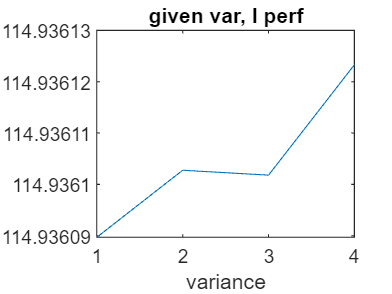

figure 
plot(perf_l_var(1,:))
% hold on 
% plot(perf_l_var(2,:))
% plot(perf_l_var(3,:))
% plot(perf_l_var(4,:))
%xlim[log(variances(1)), log(variances(end))]
xlabel('variance')
title('given var, l perf')


figure 

plot(perf_l_var(:,1))
 hold on 
plot(perf_l_var(:, 2))
plot(perf_l_var(3,:))
plot(perf_l_var(4,:))
%xlim[log(variances(1)), log(variances(end))]
xlabel('lengthscale')
title('given l, var perf')


Disucssion: here we tested for the limits of both hyperparmeters values, it was forseen to have such a bad performance. 

From the first graph we see that given the lengthscale, augmenting variance does npt improve.  Comparing all lengthscale perf given var, we can see that the best that performed was with difference the smallest one (the ranges tested differed enormously). with this we can settle to look for lengthscale values between the first and second values of l:  log (0.1 and 3.3 *10^4)  

variance will be tested across the different lengthscales too. The difference in performance between the first and second value do not differ too much and then skyrocket in the last value log(15) =2.78

meanfunc = [];    
covfunc = @covSEiso;   
likfunc = @likGauss; sn = 0.1;
%initial param from documentation
hypSE = struct('mean', [] , 'cov', [0 0], 'lik', -1);
%ranges 
currentDateTime = datestr(now, 'yyyy_mm_dd_HH_MM_SS');
% Create the log file name with the current date and time
logFileName = strcat('log_', currentDateTime, '.txt');

logFile = fopen(logFileName, 'w');

lengthscales = linspace(0.1, 10, 4); 
variances = linspace(0.1, 10, 4); 
bestVarT = 0; bestLT = 0; bestMAPET= 300;
perf_l_var = zeros(length(lengthscales), length(variances));

for i = 1: numel(lengthscales)
    for j = 1: numel(variances)
        hypSE.cov(1) = lengthscales(i);
        hypSE.cov(2) = variances(j);
        mapeVals = zeros(numtestsets, 1);
       %every fold
       for k = 1:numtestsets
      
        xtrain = XT(cv.training(k)); ytrain = YT(cv.training(k));
        xtest = XT(cv.test(k)); ytest = YT(cv.test(k));
        hypSE = minimize(hypSE, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain);
        [ymu ,ys2 ,fmu, fs2, lp] = gp(hypSE, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain, xtest);
        mape_val = calculateMAPE(ytest, ymu)
        mapeVals(k) = mape_val;

        % Log the length scale, variance, and MAPE for each iteration
        loggedLengthScale = hypSE.cov(1);
        loggedVariance = hypSE.cov(2);
        loggedMAPE = mape_val;

        % Write the logged values to the log file
        fprintf(logFile, 'Iteration lengthscale: %d\n', i);
        fprintf(logFile, 'Iteration variance: %d\n', j);
        fprintf(logFile, 'Length Scale: %.2f\n', loggedLengthScale);
        fprintf(logFile, 'Variance: %.2f\n', loggedVariance);
        fprintf(logFile, 'MAPE: %.2f\n', loggedMAPE);
        fprintf(logFile, '----------------------------\n');
       end
       perf_l_var(i,j) = mean(mapeVals) 
       if bestMAPET> mean(mapeVals)
           bestMAPET = mean(mapeVals);
           bestLT = lengthscales(i);
           bestVarT = variances(j);
        end
    end
end 

Function evaluation      0;  Value 2.039427e+01
Function evaluation      7;  Value -5.810623e+01
Function evaluation     10;  Value -5.839671e+01
Function evaluation     15;  Value -5.901865e+01
Function evaluation     19;  Value -5.901875e+01
Function evaluation     25;  Value -5.903051e+01
Function evaluation     27;  Value -5.903158e+01
Function evaluation     29;  Value -5.903159e+01
Function evaluation     33;  Value -5.903172e+01
Function evaluation     37;  Value -5.903172e+01
Function evaluation     42;  Value -5.903173e+01
Function evaluation     46;  Value -5.903173e+01
Function evaluation     48;  Value -5.903173e+01


mape_val = 105.5924

Function evaluation      0;  Value -6.243377e+01
Function evaluation      3;  Value -6.248548e+01
Function evaluation      5;  Value -6.248577e+01
Function evaluation      7;  Value -6.248580e+01
Function evaluation     10;  Value -6.248605e+01
Function evaluation     14;  Value -6.248605e+01
Function evaluation     19;  Value -6.248605e+01
Function evaluation     23;  Value -6.248605e+01
Function evaluation     26;  Value -6.248605e+01
Function evaluation     29;  Value -6.248605e+01
Function evaluation     31;  Value -6.248605e+01
Function evaluation     35;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     23;  Value -6.233873e+01
Function evaluation     25;  Value -6.233873e+01
Function evaluation     30;  Value -6.233873e+01
Function evaluation     36;  Value -6.233873e+01
Function evaluation     45;  Value -6.233873e+01
Function evaluation     47;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     20;  Value -6.307146e+01
Function evaluation     26;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     56;  Value -5.945208e+01
Function evaluation     58;  Value -5.945208e+01


mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8414

Function evaluation      0;  Value -5.755147e+01
Function evaluation      3;  Value -5.766066e+01
Function evaluation      5;  Value -5.766066e+01
Function evaluation     11;  Value -5.766089e+01
Function evaluation     15;  Value -5.766175e+01
Function evaluation     17;  Value -5.766178e+01
Function evaluation     18;  Value -5.766181e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     24;  Value -5.766181e+01
Function evaluation     27;  Value -5.766181e+01
Function evaluation     32;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     55;  Value -6.020292e+01
Function evaluation     57;  Value -6.020292e+01
Function evaluation     60;  Value -6.020292e+01
Function evaluation     62;  Value -6.020292e+01
Function evaluation     66;  Value -6.020292e+01
Function evaluation 

mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     34;  Value -6.164787e+01
Function evaluation     37;  Value -6.164787e+01
Function evaluation     40;  Value -6.164787e+01
Function evaluation     42;  Value -6.164787e+01
Function evaluation     44;  Value -6.164787e+01
Function evaluation     47;  Value -6.164787e+01
Function evaluation     49;  Value -6.164787e+01
Function evaluation     52;  Value -6.164787e+01
Function evaluation     54;  Value -6.164787e+01
Function evaluation     57;  Value -6.164787e+01
Function evaluation     59;  Value -6.164787e+01
Function evaluation     62;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     24;  Value -5.987141e+01
Function evaluation     28;  Value -5.987141e+01
Function evaluation     32;  Value -5.987141e+01
Function evaluation     37;  Value -5.987141e+01
Function evaluation     40;  Value -5.987141e+01
Function evaluation     45;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -5.202680e+01
Function evaluation      4;  Value -5.204418e+01
Function evaluation     12;  Value -5.852410e+01
Function evaluation     15;  Value -5.857460e+01
Function evaluation     17;  Value -5.859050e+01
Function evaluation     19;  Value -5.859307e+01
Function evaluation     21;  Value -5.860135e+01
Function evaluation     23;  Value -5.860316e+01
Function evaluation     26;  Value -5.861993e+01
Function evaluation     28;  Value -5.862570e+01
Function evaluation     33;  Value -5.881981e+01
Function evaluation     36;  Value -5.882239e+01
Function evaluation     40;  Value -5.887993e+01
Function evaluation     43;  Value -5.888123e+01
Function evaluation     48;  Value -5.896278e+01
Function evaluation     51;  Value -5.896603e+01
Function evaluation     55;  Value -5.900022e+01
Function evaluation     58;  Value -5.900159e+01
Function evaluation     61;  Value -5.900827e+01
Function evaluation     63;  Value -5.900935e+01
Function evaluation 

mape_val = 105.5649

Function evaluation      0;  Value -6.242812e+01
Function evaluation      3;  Value -6.247974e+01
Function evaluation      6;  Value -6.248246e+01
Function evaluation      8;  Value -6.248354e+01
Function evaluation     10;  Value -6.248442e+01
Function evaluation     12;  Value -6.248573e+01
Function evaluation     14;  Value -6.248605e+01
Function evaluation     16;  Value -6.248605e+01
Function evaluation     19;  Value -6.248605e+01
Function evaluation     22;  Value -6.248605e+01
Function evaluation     27;  Value -6.248605e+01
Function evaluation     31;  Value -6.248605e+01
Function evaluation     35;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     23;  Value -6.233873e+01
Function evaluation     25;  Value -6.233873e+01
Function evaluation     27;  Value -6.233873e+01
Function evaluation     29;  Value -6.233873e+01
Function evaluation     34;  Value -6.233873e+01
Function evaluation     36;  Value -6.233873e+01
Function evaluation     41;  Value -6.233873e+01
Function evaluation     45;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     21;  Value -6.307146e+01
Function evaluation     23;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     48;  Value -5.945208e+01
Function evaluation     51;  Value -5.945208e+01
Function evaluation     57;  Value -5.945208e+01
Function evaluation     60;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8418

Function evaluation      0;  Value -5.755170e+01
Function evaluation      3;  Value -5.766072e+01
Function evaluation      5;  Value -5.766072e+01
Function evaluation     12;  Value -5.766093e+01
Function evaluation     16;  Value -5.766177e+01
Function evaluation     18;  Value -5.766179e+01
Function evaluation     20;  Value -5.766181e+01
Function evaluation     22;  Value -5.766181e+01
Function evaluation     24;  Value -5.766181e+01
Function evaluation     26;  Value -5.766181e+01
Function evaluation     28;  Value -5.766181e+01
Function evaluation     30;  Value -5.766181e+01
Function evaluation     32;  Value -5.766181e+01
Function evaluation     34;  Value -5.766181e+01
Function evaluation     36;  Value -5.766181e+01
Function evaluation     38;  Value -5.766181e+01
Function evaluation     40;  Value -5.766181e+01
Function evaluation     42;  Value -5.766181e+01
Function evaluation     45;  Value -5.766181e+01
Function evaluation     47;  Value -5.766181e+01
Function evaluation 

mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     51;  Value -6.020292e+01
Function evaluation     53;  Value -6.020292e+01
Function evaluation     57;  Value -6.020292e+01
Function evaluation     60;  Value -6.020292e+01
Function evaluation     62;  Value -6.020292e+01
Function evaluation     64;  Value -6.020292e+01
Function evaluation 

mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     35;  Value -6.164787e+01
Function evaluation     38;  Value -6.164787e+01
Function evaluation     39;  Value -6.164787e+01
Function evaluation     42;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     48;  Value -6.164787e+01
Function evaluation     50;  Value -6.164787e+01
Function evaluation     54;  Value -6.164787e+01
Function evaluation     57;  Value -6.164787e+01
Function evaluation     64;  Value -6.164787e+01
Function evaluation     66;  Value -6.164787e+01
Function evaluation     73;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     24;  Value -5.987141e+01
Function evaluation     29;  Value -5.987141e+01
Function evaluation     31;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9334         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -4.542714e+01
Function evaluation      4;  Value -4.544453e+01
Function evaluation     19;  Value -5.773156e+01
Function evaluation     24;  Value -5.784310e+01
Function evaluation     26;  Value -5.786794e+01
Function evaluation     28;  Value -5.787137e+01
Function evaluation     31;  Value -5.789071e+01
Function evaluation     33;  Value -5.789917e+01
Function evaluation     37;  Value -5.799229e+01
Function evaluation     40;  Value -5.800086e+01
Function evaluation     54;  Value -5.856609e+01
Function evaluation     57;  Value -5.859944e+01
Function evaluation     60;  Value -5.871576e+01
Function evaluation     62;  Value -5.871582e+01
Function evaluation     66;  Value -5.871582e+01
Function evaluation     69;  Value -5.871582e+01
Function evaluation     72;  Value -5.871582e+01
Function evaluation     76;  Value -5.871582e+01
Function evaluation     79;  Value -5.871582e+01
Function evaluation     84;  Value -5.871582e+01
Function evaluation 

mape_val = 105.4191

Function evaluation      0;  Value -6.211842e+01
Function evaluation      3;  Value -6.217057e+01
Function evaluation      5;  Value -6.217113e+01
Function evaluation      7;  Value -6.217124e+01
Function evaluation     10;  Value -6.217199e+01
Function evaluation     14;  Value -6.217199e+01
Function evaluation     26;  Value -6.242055e+01
Function evaluation     30;  Value -6.242057e+01
Function evaluation     37;  Value -6.242802e+01
Function evaluation     40;  Value -6.248198e+01
Function evaluation     43;  Value -6.248235e+01
Function evaluation     47;  Value -6.248432e+01
Function evaluation     50;  Value -6.248446e+01
Function evaluation     55;  Value -6.248605e+01
Function evaluation     59;  Value -6.248605e+01
Function evaluation     63;  Value -6.248605e+01
Function evaluation     67;  Value -6.248605e+01
Function evaluation     71;  Value -6.248605e+01
Function evaluation     74;  Value -6.248605e+01
Function evaluation     79;  Value -6.248605e+01
Function evaluation 

mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     24;  Value -6.233873e+01
Function evaluation     26;  Value -6.233873e+01
Function evaluation     32;  Value -6.233873e+01
Function evaluation     34;  Value -6.233873e+01
Function evaluation     40;  Value -6.233873e+01
Function evaluation     44;  Value -6.233873e+01
Function evaluation     49;  Value -6.233873e+01
Function evaluation     51;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     21;  Value -6.307146e+01
Function evaluation     31;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     54;  Value -5.945208e+01
Function evaluation     60;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8414

Function evaluation      0;  Value -5.755147e+01
Function evaluation      3;  Value -5.766066e+01
Function evaluation      5;  Value -5.766066e+01
Function evaluation     11;  Value -5.766089e+01
Function evaluation     15;  Value -5.766175e+01
Function evaluation     17;  Value -5.766178e+01
Function evaluation     18;  Value -5.766181e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     26;  Value -5.766181e+01
Function evaluation     30;  Value -5.766181e+01
Function evaluation     34;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     51;  Value -6.020292e+01
Function evaluation     53;  Value -6.020292e+01
Function evaluation     58;  Value -6.020292e+01
Function evaluation     60;  Value -6.020292e+01
Function evaluation     62;  Value -6.020292e+01


mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     34;  Value -6.164787e+01
Function evaluation     37;  Value -6.164787e+01
Function evaluation     40;  Value -6.164787e+01
Function evaluation     43;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     48;  Value -6.164787e+01
Function evaluation     50;  Value -6.164787e+01
Function evaluation     54;  Value -6.164787e+01
Function evaluation     57;  Value -6.164787e+01
Function evaluation     61;  Value -6.164787e+01


mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     33;  Value -5.987141e+01
Function evaluation     35;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9334  114.9188         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -3.882507e+01
Function evaluation      4;  Value -3.884243e+01
Function evaluation     24;  Value -5.630092e+01
Function evaluation     28;  Value -5.659649e+01
Function evaluation     30;  Value -5.707019e+01
Function evaluation     32;  Value -5.709645e+01
Function evaluation     34;  Value -5.711409e+01
Function evaluation     36;  Value -5.712938e+01
Function evaluation     38;  Value -5.714007e+01
Function evaluation     40;  Value -5.716565e+01
Function evaluation     42;  Value -5.718523e+01
Function evaluation     44;  Value -5.722881e+01
Function evaluation     45;  Value -5.727109e+01
Function evaluation     56;  Value -5.861450e+01
Function evaluation     59;  Value -5.862000e+01
Function evaluation     63;  Value -5.871578e+01
Function evaluation     66;  Value -5.871581e+01
Function evaluation     70;  Value -5.871581e+01


mape_val = 105.4209

Function evaluation      0;  Value -6.211910e+01
Function evaluation      3;  Value -6.217081e+01
Function evaluation      5;  Value -6.217107e+01
Function evaluation      7;  Value -6.217110e+01
Function evaluation     10;  Value -6.217135e+01
Function evaluation     15;  Value -6.217135e+01
Function evaluation     19;  Value -6.217135e+01
Function evaluation     20;  Value -6.217135e+01
Function evaluation     25;  Value -6.217135e+01
Function evaluation     31;  Value -6.217135e+01
Function evaluation     35;  Value -6.217135e+01
Function evaluation     55;  Value -6.217135e+01


mape_val = 139.7837

Function evaluation      0;  Value -6.202675e+01
Function evaluation      5;  Value -6.202683e+01
Function evaluation      9;  Value -6.202690e+01
Function evaluation     14;  Value -6.202690e+01


mape_val = 149.4542

Function evaluation      0;  Value -6.275939e+01
Function evaluation      5;  Value -6.276137e+01
Function evaluation      9;  Value -6.276146e+01


mape_val = 152.5036

Function evaluation      0;  Value -5.908955e+01
Function evaluation      3;  Value -5.913914e+01
Function evaluation      5;  Value -5.913943e+01
Function evaluation      8;  Value -5.913949e+01
Function evaluation     10;  Value -5.913954e+01
Function evaluation     12;  Value -5.913954e+01
Function evaluation     18;  Value -5.913954e+01


mape_val = 105.8057

Function evaluation      0;  Value -6.261777e+01
Function evaluation      3;  Value -6.266412e+01
Function evaluation      5;  Value -6.266428e+01
Function evaluation      7;  Value -6.266428e+01
Function evaluation     11;  Value -6.266428e+01
Function evaluation     14;  Value -6.266428e+01
Function evaluation     17;  Value -6.266428e+01


mape_val = 76.7564

Function evaluation      0;  Value -5.723455e+01
Function evaluation      3;  Value -5.734373e+01
Function evaluation      5;  Value -5.734391e+01
Function evaluation      9;  Value -5.734422e+01
Function evaluation     14;  Value -5.734422e+01


mape_val = 97.8067

Function evaluation      0;  Value -5.987231e+01
Function evaluation      4;  Value -5.989225e+01
Function evaluation      8;  Value -5.989227e+01
Function evaluation     12;  Value -5.989227e+01
Function evaluation     16;  Value -5.989227e+01


mape_val = 101.8942

Function evaluation      0;  Value -6.132774e+01
Function evaluation      4;  Value -6.133575e+01
Function evaluation      8;  Value -6.133601e+01
Function evaluation     12;  Value -6.133601e+01
Function evaluation     15;  Value -6.133601e+01


mape_val = 117.6511

Function evaluation      0;  Value -5.954868e+01
Function evaluation      4;  Value -5.956059e+01
Function evaluation      7;  Value -5.956060e+01
Function evaluation      9;  Value -5.956060e+01
Function evaluation     13;  Value -5.956061e+01
Function evaluation     18;  Value -5.956061e+01


mape_val = 100.7165

perf_l_var =   114.9361  114.9334  114.9188  114.7793
         0         0         0         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -1.159796e+01
Function evaluation      6;  Value -3.987432e+01
Function evaluation      8;  Value -5.479458e+01
Function evaluation     10;  Value -5.638453e+01
Function evaluation     12;  Value -5.758537e+01
Function evaluation     14;  Value -5.759044e+01
Function evaluation     16;  Value -5.760390e+01
Function evaluation     18;  Value -5.760671e+01
Function evaluation     22;  Value -5.764040e+01
Function evaluation     24;  Value -5.764461e+01
Function evaluation     28;  Value -5.770432e+01
Function evaluation     30;  Value -5.771661e+01
Function evaluation     33;  Value -5.783452e+01
Function evaluation     35;  Value -5.789333e+01
Function evaluation     38;  Value -5.806963e+01
Function evaluation     40;  Value -5.816421e+01
Function evaluation     43;  Value -5.853438e+01
Function evaluation     46;  Value -5.854961e+01
Function evaluation     48;  Value -5.856130e+01
Function evaluation     50;  Value -5.856414e+01
Function evaluation 

mape_val = 105.5814

Function evaluation      0;  Value -6.243190e+01
Function evaluation      3;  Value -6.248521e+01
Function evaluation      5;  Value -6.248555e+01
Function evaluation      8;  Value -6.248555e+01
Function evaluation     13;  Value -6.248582e+01
Function evaluation     15;  Value -6.248588e+01
Function evaluation     17;  Value -6.248605e+01
Function evaluation     19;  Value -6.248605e+01
Function evaluation     21;  Value -6.248605e+01
Function evaluation     23;  Value -6.248605e+01
Function evaluation     24;  Value -6.248605e+01
Function evaluation     27;  Value -6.248605e+01
Function evaluation     29;  Value -6.248605e+01
Function evaluation     34;  Value -6.248605e+01
Function evaluation     38;  Value -6.248605e+01
Function evaluation     42;  Value -6.248605e+01
Function evaluation     46;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     23;  Value -6.233873e+01
Function evaluation     25;  Value -6.233873e+01
Function evaluation     29;  Value -6.233873e+01
Function evaluation     31;  Value -6.233873e+01
Function evaluation     34;  Value -6.233873e+01
Function evaluation     36;  Value -6.233873e+01
Function evaluation     39;  Value -6.233873e+01
Function evaluation     42;  Value -6.233873e+01
Function evaluation     47;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     22;  Value -6.307146e+01
Function evaluation     38;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     54;  Value -5.945208e+01
Function evaluation     57;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296743e+01
Function evaluation 

mape_val = 76.8415

Function evaluation      0;  Value -5.755153e+01
Function evaluation      3;  Value -5.766070e+01
Function evaluation      5;  Value -5.766070e+01
Function evaluation     12;  Value -5.766091e+01
Function evaluation     16;  Value -5.766175e+01
Function evaluation     18;  Value -5.766178e+01
Function evaluation     19;  Value -5.766181e+01
Function evaluation     22;  Value -5.766181e+01
Function evaluation     27;  Value -5.766181e+01
Function evaluation     30;  Value -5.766181e+01
Function evaluation     45;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     55;  Value -6.020292e+01
Function evaluation     57;  Value -6.020292e+01
Function evaluation     58;  Value -6.020292e+01
Function evaluation     60;  Value -6.020292e+01
Function evaluation     67;  Value -6.020292e+01
Function evaluation 

mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     35;  Value -6.164787e+01
Function evaluation     38;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     43;  Value -6.164787e+01
Function evaluation     47;  Value -6.164787e+01
Function evaluation     49;  Value -6.164787e+01
Function evaluation     50;  Value -6.164787e+01
Function evaluation     52;  Value -6.164787e+01
Function evaluation     65;  Value -6.164787e+01
Function evaluation     68;  Value -6.164787e+01


mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     29;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9334  114.9188  114.7793
  114.9350         0         0         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -5.503884e+01
Function evaluation      4;  Value -5.505385e+01
Function evaluation     10;  Value -5.611272e+01
Function evaluation     13;  Value -5.612321e+01
Function evaluation     28;  Value -5.885921e+01
Function evaluation     32;  Value -5.886611e+01
Function evaluation     36;  Value -5.893015e+01
Function evaluation     39;  Value -5.893277e+01
Function evaluation     44;  Value -5.902975e+01
Function evaluation     47;  Value -5.903131e+01
Function evaluation     49;  Value -5.903165e+01
Function evaluation     51;  Value -5.903165e+01
Function evaluation     54;  Value -5.903165e+01
Function evaluation     56;  Value -5.903166e+01
Function evaluation     58;  Value -5.903166e+01
Function evaluation     60;  Value -5.903166e+01
Function evaluation     62;  Value -5.903166e+01
Function evaluation     64;  Value -5.903166e+01
Function evaluation     66;  Value -5.903166e+01
Function evaluation     68;  Value -5.903167e+01
Function evaluation 

mape_val = 105.5941

Function evaluation      0;  Value -6.243387e+01
Function evaluation      3;  Value -6.248551e+01
Function evaluation      5;  Value -6.248579e+01
Function evaluation      7;  Value -6.248581e+01
Function evaluation     10;  Value -6.248602e+01
Function evaluation     12;  Value -6.248605e+01
Function evaluation     15;  Value -6.248605e+01
Function evaluation     18;  Value -6.248605e+01
Function evaluation     22;  Value -6.248605e+01
Function evaluation     25;  Value -6.248605e+01
Function evaluation     29;  Value -6.248605e+01
Function evaluation     32;  Value -6.248605e+01
Function evaluation     36;  Value -6.248605e+01
Function evaluation     39;  Value -6.248605e+01
Function evaluation     43;  Value -6.248605e+01
Function evaluation     46;  Value -6.248605e+01
Function evaluation     50;  Value -6.248605e+01
Function evaluation     53;  Value -6.248605e+01
Function evaluation     57;  Value -6.248605e+01
Function evaluation     60;  Value -6.248605e+01
Function evaluation 

mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     24;  Value -6.233873e+01
Function evaluation     26;  Value -6.233873e+01
Function evaluation     31;  Value -6.233873e+01
Function evaluation     34;  Value -6.233873e+01
Function evaluation     40;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     22;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     54;  Value -5.945208e+01
Function evaluation     57;  Value -5.945208e+01


mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296743e+01
Function evaluation 

mape_val = 76.8416

Function evaluation      0;  Value -5.755148e+01
Function evaluation      3;  Value -5.766072e+01
Function evaluation      5;  Value -5.766072e+01
Function evaluation     12;  Value -5.766093e+01
Function evaluation     16;  Value -5.766175e+01
Function evaluation     18;  Value -5.766178e+01
Function evaluation     19;  Value -5.766181e+01
Function evaluation     22;  Value -5.766181e+01
Function evaluation     27;  Value -5.766181e+01
Function evaluation     30;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     51;  Value -6.020292e+01
Function evaluation     54;  Value -6.020292e+01
Function evaluation     58;  Value -6.020292e+01
Function evaluation     62;  Value -6.020292e+01
Function evaluation     64;  Value -6.020292e+01
Function evaluation     66;  Value -6.020292e+01
Function evaluation 

mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     36;  Value -6.164787e+01
Function evaluation     39;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     44;  Value -6.164787e+01
Function evaluation     47;  Value -6.164787e+01
Function evaluation     50;  Value -6.164787e+01
Function evaluation     52;  Value -6.164787e+01
Function evaluation     55;  Value -6.164787e+01
Function evaluation     58;  Value -6.164787e+01
Function evaluation     61;  Value -6.164787e+01
Function evaluation     63;  Value -6.164787e+01
Function evaluation     65;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     23;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9334  114.9188  114.7793
  114.9350  114.9363         0         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -4.853649e+01
Function evaluation      4;  Value -4.855675e+01
Function evaluation     20;  Value -5.496081e+01
Function evaluation     23;  Value -5.499755e+01
Function evaluation     27;  Value -5.515248e+01
Function evaluation     30;  Value -5.516211e+01
Function evaluation     35;  Value -5.571604e+01
Function evaluation     47;  Value -5.869289e+01
Function evaluation     51;  Value -5.870279e+01
Function evaluation     53;  Value -5.871569e+01
Function evaluation     55;  Value -5.871581e+01
Function evaluation     58;  Value -5.871581e+01
Function evaluation     60;  Value -5.871581e+01
Function evaluation     62;  Value -5.871581e+01


mape_val = 105.4209

Function evaluation      0;  Value -6.211910e+01
Function evaluation      3;  Value -6.217081e+01
Function evaluation      5;  Value -6.217107e+01
Function evaluation      7;  Value -6.217110e+01
Function evaluation     10;  Value -6.217135e+01
Function evaluation     15;  Value -6.217135e+01
Function evaluation     19;  Value -6.217135e+01
Function evaluation     20;  Value -6.217135e+01
Function evaluation     24;  Value -6.217135e+01
Function evaluation     30;  Value -6.217135e+01
Function evaluation     33;  Value -6.217135e+01


mape_val = 139.7837

Function evaluation      0;  Value -6.202675e+01
Function evaluation      5;  Value -6.202683e+01
Function evaluation      9;  Value -6.202690e+01
Function evaluation     14;  Value -6.202690e+01


mape_val = 149.4542

Function evaluation      0;  Value -6.275939e+01
Function evaluation      5;  Value -6.276137e+01
Function evaluation      9;  Value -6.276146e+01


mape_val = 152.5036

Function evaluation      0;  Value -5.908955e+01
Function evaluation      3;  Value -5.913914e+01
Function evaluation      5;  Value -5.913943e+01
Function evaluation      8;  Value -5.913949e+01
Function evaluation     10;  Value -5.913954e+01
Function evaluation     12;  Value -5.913954e+01
Function evaluation     19;  Value -5.913954e+01


mape_val = 105.8057

Function evaluation      0;  Value -6.261777e+01
Function evaluation      3;  Value -6.266412e+01
Function evaluation      5;  Value -6.266428e+01
Function evaluation      7;  Value -6.266428e+01
Function evaluation     11;  Value -6.266428e+01
Function evaluation     14;  Value -6.266428e+01
Function evaluation     17;  Value -6.266428e+01


mape_val = 76.7564

Function evaluation      0;  Value -5.723455e+01
Function evaluation      3;  Value -5.734373e+01
Function evaluation      5;  Value -5.734391e+01
Function evaluation      9;  Value -5.734422e+01
Function evaluation     14;  Value -5.734422e+01


mape_val = 97.8067

Function evaluation      0;  Value -5.987231e+01
Function evaluation      4;  Value -5.989225e+01
Function evaluation      8;  Value -5.989227e+01
Function evaluation     12;  Value -5.989227e+01
Function evaluation     16;  Value -5.989227e+01


mape_val = 101.8942

Function evaluation      0;  Value -6.132774e+01
Function evaluation      4;  Value -6.133575e+01
Function evaluation      8;  Value -6.133601e+01
Function evaluation     12;  Value -6.133601e+01
Function evaluation     15;  Value -6.133601e+01


mape_val = 117.6511

Function evaluation      0;  Value -5.954868e+01
Function evaluation      4;  Value -5.956059e+01
Function evaluation      7;  Value -5.956060e+01
Function evaluation      9;  Value -5.956060e+01
Function evaluation     13;  Value -5.956061e+01
Function evaluation     18;  Value -5.956061e+01
Function evaluation     20;  Value -5.956061e+01


mape_val = 100.7165

perf_l_var =   114.9361  114.9334  114.9188  114.7793
  114.9350  114.9363  114.7793         0
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value -4.193452e+01
Function evaluation      4;  Value -4.195539e+01
Function evaluation     19;  Value -5.317852e+01
Function evaluation     23;  Value -5.348942e+01
Function evaluation     25;  Value -5.389761e+01
Function evaluation     27;  Value -5.392447e+01
Function evaluation     29;  Value -5.394569e+01
Function evaluation     31;  Value -5.395607e+01
Function evaluation     33;  Value -5.396171e+01
Function evaluation     36;  Value -5.398748e+01
Function evaluation     38;  Value -5.399820e+01
Function evaluation     41;  Value -5.405021e+01
Function evaluation     43;  Value -5.407302e+01
Function evaluation     47;  Value -5.419053e+01
Function evaluation     48;  Value -5.429568e+01
Function evaluation     54;  Value -5.844155e+01
Function evaluation     57;  Value -5.845318e+01
Function evaluation     61;  Value -5.871578e+01
Function evaluation     64;  Value -5.871581e+01
Function evaluation     68;  Value -5.871581e+01
Function evaluation 

mape_val = 105.4209

Function evaluation      0;  Value -6.211910e+01
Function evaluation      3;  Value -6.217081e+01
Function evaluation      5;  Value -6.217107e+01
Function evaluation      7;  Value -6.217110e+01
Function evaluation     10;  Value -6.217135e+01
Function evaluation     15;  Value -6.217135e+01
Function evaluation     19;  Value -6.217135e+01
Function evaluation     20;  Value -6.217135e+01
Function evaluation     25;  Value -6.217135e+01
Function evaluation     31;  Value -6.217135e+01
Function evaluation     35;  Value -6.217135e+01
Function evaluation     40;  Value -6.217135e+01


mape_val = 139.7837

Function evaluation      0;  Value -6.202675e+01
Function evaluation      5;  Value -6.202683e+01
Function evaluation      9;  Value -6.202690e+01
Function evaluation     14;  Value -6.202690e+01


mape_val = 149.4542

Function evaluation      0;  Value -6.275939e+01
Function evaluation      5;  Value -6.276137e+01
Function evaluation      9;  Value -6.276146e+01


mape_val = 152.5036

Function evaluation      0;  Value -5.908955e+01
Function evaluation      3;  Value -5.913914e+01
Function evaluation      5;  Value -5.913943e+01
Function evaluation      8;  Value -5.913949e+01
Function evaluation     10;  Value -5.913954e+01
Function evaluation     12;  Value -5.913954e+01
Function evaluation     25;  Value -5.913954e+01
Function evaluation     40;  Value -5.913954e+01


mape_val = 105.8057

Function evaluation      0;  Value -6.261777e+01
Function evaluation      3;  Value -6.266412e+01
Function evaluation      5;  Value -6.266428e+01
Function evaluation      7;  Value -6.266428e+01
Function evaluation     11;  Value -6.266428e+01
Function evaluation     14;  Value -6.266428e+01
Function evaluation     17;  Value -6.266428e+01


mape_val = 76.7564

Function evaluation      0;  Value -5.723455e+01
Function evaluation      3;  Value -5.734373e+01
Function evaluation      5;  Value -5.734391e+01
Function evaluation      9;  Value -5.734422e+01
Function evaluation     14;  Value -5.734422e+01


mape_val = 97.8067

Function evaluation      0;  Value -5.987231e+01
Function evaluation      4;  Value -5.989225e+01
Function evaluation      8;  Value -5.989227e+01
Function evaluation     12;  Value -5.989227e+01
Function evaluation     16;  Value -5.989227e+01


mape_val = 101.8942

Function evaluation      0;  Value -6.132774e+01
Function evaluation      4;  Value -6.133575e+01
Function evaluation      8;  Value -6.133601e+01
Function evaluation     12;  Value -6.133601e+01
Function evaluation     15;  Value -6.133601e+01


mape_val = 117.6511

Function evaluation      0;  Value -5.954868e+01
Function evaluation      4;  Value -5.956059e+01
Function evaluation      7;  Value -5.956060e+01
Function evaluation      9;  Value -5.956060e+01
Function evaluation     13;  Value -5.956061e+01
Function evaluation     18;  Value -5.956061e+01


mape_val = 100.7165

perf_l_var =   114.9361  114.9334  114.9188  114.7793
  114.9350  114.9363  114.7793  114.7793
         0         0         0         0
         0         0         0         0


Function evaluation      0;  Value 1.016599e+02
Function evaluation      7;  Value 4.473051e+01
Function evaluation      9;  Value 4.458865e+01
Function evaluation     12;  Value 4.455280e+01
Function evaluation     14;  Value 4.449189e+01
Function evaluation     17;  Value 4.416538e+01
Function evaluation     20;  Value 4.416037e+01
Function evaluation     25;  Value 4.415730e+01
Function evaluation     28;  Value 4.415726e+01
Function evaluation     53;  Value -5.887928e+01
Function evaluation     56;  Value -5.892592e+01
Function evaluation     61;  Value -5.897437e+01
Function evaluation     63;  Value -5.902651e+01
Function evaluation     66;  Value -5.902729e+01
Function evaluation     69;  Value -5.903145e+01
Function evaluation     73;  Value -5.903146e+01
Function evaluation     78;  Value -5.903158e+01
Function evaluation     81;  Value -5.903158e+01
Function evaluation     86;  Value -5.903171e+01
Function evaluation     90;  Value -5.903171e+01
Function evaluation     94;  

mape_val = 105.5922

Function evaluation      0;  Value -6.243378e+01
Function evaluation      3;  Value -6.248548e+01
Function evaluation      5;  Value -6.248577e+01
Function evaluation      7;  Value -6.248580e+01
Function evaluation     10;  Value -6.248605e+01
Function evaluation     14;  Value -6.248605e+01
Function evaluation     19;  Value -6.248605e+01
Function evaluation     22;  Value -6.248605e+01
Function evaluation     24;  Value -6.248605e+01


mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     23;  Value -6.233873e+01
Function evaluation     25;  Value -6.233873e+01
Function evaluation     29;  Value -6.233873e+01
Function evaluation     31;  Value -6.233873e+01
Function evaluation     35;  Value -6.233873e+01
Function evaluation     38;  Value -6.233873e+01
Function evaluation     42;  Value -6.233873e+01
Function evaluation     44;  Value -6.233873e+01
Function evaluation     47;  Value -6.233873e+01
Function evaluation     49;  Value -6.233873e+01
Function evaluation     58;  Value -6.233873e+01
Function evaluation     60;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     20;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     54;  Value -5.945208e+01
Function evaluation     56;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8414

Function evaluation      0;  Value -5.755146e+01
Function evaluation      3;  Value -5.766066e+01
Function evaluation      5;  Value -5.766066e+01
Function evaluation     11;  Value -5.766089e+01
Function evaluation     15;  Value -5.766175e+01
Function evaluation     17;  Value -5.766178e+01
Function evaluation     18;  Value -5.766181e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     24;  Value -5.766181e+01
Function evaluation     27;  Value -5.766181e+01
Function evaluation     30;  Value -5.766181e+01
Function evaluation     32;  Value -5.766181e+01
Function evaluation     55;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     55;  Value -6.020292e+01
Function evaluation     57;  Value -6.020292e+01
Function evaluation     62;  Value -6.020292e+01
Function evaluation     64;  Value -6.020292e+01
Function evaluation     68;  Value -6.020292e+01


mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     36;  Value -6.164787e+01
Function evaluation     39;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     42;  Value -6.164787e+01
Function evaluation     44;  Value -6.164787e+01
Function evaluation     49;  Value -6.164787e+01
Function evaluation     52;  Value -6.164787e+01


mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     29;  Value -5.987141e+01
Function evaluation     33;  Value -5.987141e+01
Function evaluation     45;  Value -5.987141e+01
Function evaluation     48;  Value -5.987141e+01
Function evaluation     53;  Value -5.987141e+01
Function evaluation     55;  Value -5.987141e+01
Function evaluation     61;  Value -5.987141e+01
Function evaluation     66;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9334  114.9188  114.7793
  114.9350  114.9363  114.7793  114.7793
  114.9361         0         0         0
         0         0         0         0


Function evaluation      0;  Value -8.404931e+00
Function evaluation      6;  Value -3.661733e+01
Function evaluation      8;  Value -5.152072e+01
Function evaluation     10;  Value -5.310604e+01
Function evaluation     12;  Value -5.429911e+01
Function evaluation     14;  Value -5.430497e+01
Function evaluation     16;  Value -5.432273e+01
Function evaluation     18;  Value -5.432581e+01
Function evaluation     22;  Value -5.435737e+01
Function evaluation     25;  Value -5.435960e+01
Function evaluation     28;  Value -5.437983e+01
Function evaluation     30;  Value -5.438542e+01
Function evaluation     34;  Value -5.444563e+01
Function evaluation     36;  Value -5.447143e+01
Function evaluation     39;  Value -5.469468e+01
Function evaluation     41;  Value -5.497499e+01
Function evaluation     45;  Value -5.599514e+01
Function evaluation     47;  Value -5.642061e+01
Function evaluation     50;  Value -5.799991e+01
Function evaluation     53;  Value -5.811133e+01
Function evaluation 

mape_val = 105.4209

Function evaluation      0;  Value -6.211910e+01
Function evaluation      3;  Value -6.217082e+01
Function evaluation      5;  Value -6.217108e+01
Function evaluation      7;  Value -6.217110e+01
Function evaluation     10;  Value -6.217136e+01
Function evaluation     15;  Value -6.217136e+01
Function evaluation     19;  Value -6.217136e+01
Function evaluation     20;  Value -6.217136e+01
Function evaluation     22;  Value -6.217136e+01
Function evaluation     24;  Value -6.217136e+01
Function evaluation     27;  Value -6.217136e+01
Function evaluation     29;  Value -6.217136e+01
Function evaluation     31;  Value -6.217136e+01
Function evaluation     33;  Value -6.217136e+01
Function evaluation     35;  Value -6.217136e+01
Function evaluation     37;  Value -6.217136e+01
Function evaluation     40;  Value -6.217136e+01
Function evaluation     42;  Value -6.217136e+01
Function evaluation     45;  Value -6.217136e+01
Function evaluation     47;  Value -6.217136e+01
Function evaluation 

mape_val = 139.9762

Function evaluation      0;  Value -6.233582e+01
Function evaluation      5;  Value -6.233585e+01
Function evaluation     11;  Value -6.233873e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     22;  Value -6.233873e+01
Function evaluation     24;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     23;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     54;  Value -5.945208e+01
Function evaluation     57;  Value -5.945208e+01


mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296742e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296743e+01
Function evaluation 

mape_val = 76.8414

Function evaluation      0;  Value -5.755148e+01
Function evaluation      3;  Value -5.766068e+01
Function evaluation      5;  Value -5.766068e+01
Function evaluation     11;  Value -5.766089e+01
Function evaluation     15;  Value -5.766174e+01
Function evaluation     19;  Value -5.766174e+01
Function evaluation     25;  Value -5.766181e+01
Function evaluation     30;  Value -5.766181e+01
Function evaluation     34;  Value -5.766181e+01
Function evaluation     37;  Value -5.766181e+01
Function evaluation     41;  Value -5.766181e+01
Function evaluation     43;  Value -5.766181e+01
Function evaluation     46;  Value -5.766181e+01
Function evaluation     68;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     56;  Value -6.020292e+01
Function evaluation     58;  Value -6.020292e+01
Function evaluation     63;  Value -6.020292e+01


mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     35;  Value -6.164787e+01
Function evaluation     38;  Value -6.164787e+01
Function evaluation     40;  Value -6.164787e+01
Function evaluation     43;  Value -6.164787e+01
Function evaluation     46;  Value -6.164787e+01
Function evaluation     50;  Value -6.164787e+01
Function evaluation     52;  Value -6.164787e+01
Function evaluation     55;  Value -6.164787e+01
Function evaluation     57;  Value -6.164787e+01
Function evaluation     60;  Value -6.164787e+01
Function evaluation     62;  Value -6.164787e+01
Function evaluation     65;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9334  114.9188  114.7793
  114.9350  114.9363  114.7793  114.7793
  114.9361  114.9207         0         0
         0         0         0         0


Function evaluation      0;  Value -5.173874e+01
Function evaluation      4;  Value -5.175375e+01
Function evaluation     10;  Value -5.281322e+01
Function evaluation     13;  Value -5.282372e+01
Function evaluation     22;  Value -5.868699e+01
Function evaluation     26;  Value -5.871410e+01
Function evaluation     28;  Value -5.871579e+01
Function evaluation     31;  Value -5.871582e+01
Function evaluation     34;  Value -5.871582e+01
Function evaluation     37;  Value -5.871582e+01
Function evaluation     40;  Value -5.871582e+01
Function evaluation     42;  Value -5.871582e+01
Function evaluation     46;  Value -5.871582e+01
Function evaluation     48;  Value -5.871582e+01
Function evaluation     70;  Value -5.881489e+01
Function evaluation     72;  Value -5.887737e+01
Function evaluation     74;  Value -5.897038e+01
Function evaluation     76;  Value -5.898392e+01
Function evaluation     78;  Value -5.898516e+01
Function evaluation     80;  Value -5.898765e+01
Function evaluation 

mape_val = 105.5372

Function evaluation      0;  Value -6.240318e+01
Function evaluation      3;  Value -6.245595e+01
Function evaluation      6;  Value -6.246460e+01
Function evaluation      8;  Value -6.247081e+01
Function evaluation      9;  Value -6.247595e+01
Function evaluation     12;  Value -6.247608e+01
Function evaluation     16;  Value -6.247805e+01
Function evaluation     19;  Value -6.247824e+01
Function evaluation     22;  Value -6.247948e+01
Function evaluation     24;  Value -6.247980e+01
Function evaluation     27;  Value -6.248165e+01
Function evaluation     29;  Value -6.248199e+01
Function evaluation     32;  Value -6.248334e+01
Function evaluation     34;  Value -6.248349e+01
Function evaluation     37;  Value -6.248403e+01
Function evaluation     39;  Value -6.248409e+01
Function evaluation     42;  Value -6.248428e+01
Function evaluation     44;  Value -6.248430e+01
Function evaluation     47;  Value -6.248445e+01
Function evaluation     49;  Value -6.248447e+01
Function evaluation 

mape_val = 139.9583

Function evaluation      0;  Value -6.233859e+01
Function evaluation      5;  Value -6.233867e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     25;  Value -6.233873e+01
Function evaluation     27;  Value -6.233873e+01
Function evaluation     32;  Value -6.233873e+01
Function evaluation     35;  Value -6.233873e+01
Function evaluation     39;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     23;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     46;  Value -5.945208e+01
Function evaluation     49;  Value -5.945208e+01
Function evaluation     55;  Value -5.945208e+01
Function evaluation     58;  Value -5.945208e+01


mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296743e+01
Function evaluation 

mape_val = 76.8417

Function evaluation      0;  Value -5.755152e+01
Function evaluation      3;  Value -5.766070e+01
Function evaluation      5;  Value -5.766070e+01
Function evaluation     11;  Value -5.766092e+01
Function evaluation     15;  Value -5.766177e+01
Function evaluation     17;  Value -5.766178e+01
Function evaluation     19;  Value -5.766181e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     23;  Value -5.766181e+01
Function evaluation     25;  Value -5.766181e+01
Function evaluation     27;  Value -5.766181e+01
Function evaluation     29;  Value -5.766181e+01
Function evaluation     31;  Value -5.766181e+01
Function evaluation     33;  Value -5.766181e+01
Function evaluation     34;  Value -5.766181e+01
Function evaluation     36;  Value -5.766181e+01
Function evaluation     38;  Value -5.766181e+01
Function evaluation     40;  Value -5.766181e+01
Function evaluation     43;  Value -5.766181e+01
Function evaluation     45;  Value -5.766181e+01
Function evaluation 

mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     55;  Value -6.020292e+01
Function evaluation     57;  Value -6.020292e+01
Function evaluation     63;  Value -6.020292e+01


mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     35;  Value -6.164787e+01
Function evaluation     38;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     45;  Value -6.164787e+01
Function evaluation     46;  Value -6.164787e+01
Function evaluation     48;  Value -6.164787e+01
Function evaluation     51;  Value -6.164787e+01
Function evaluation     54;  Value -6.164787e+01
Function evaluation     56;  Value -6.164787e+01
Function evaluation     59;  Value -6.164787e+01
Function evaluation     61;  Value -6.164787e+01
Function evaluation     63;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     16;  Value -5.987141e+01
Function evaluation     22;  Value -5.987141e+01
Function evaluation     27;  Value -5.987141e+01
Function evaluation     31;  Value -5.987141e+01
Function evaluation     37;  Value -5.987141e+01
Function evaluation     43;  Value -5.987141e+01
Function evaluation     45;  Value -5.987141e+01
Function evaluation     48;  Value -5.987141e+01
Function evaluation     50;  Value -5.987141e+01
Function evaluation     52;  Value -5.987141e+01
Function evaluation     54;  Value -5.987141e+01
Function evaluation     59;  Value -5.987141e+01
Function evaluation     62;  Value -5.987141e+01
Function evaluation     65;  Value -5.987141e+01
Function evaluation     67;  Value -5.987141e+01
Function evaluation 

mape_val = 100.8616

perf_l_var =   114.9361  114.9334  114.9188  114.7793
  114.9350  114.9363  114.7793  114.7793
  114.9361  114.9207  114.9306         0
         0         0         0         0


Function evaluation      0;  Value -4.523552e+01
Function evaluation      4;  Value -4.525498e+01
Function evaluation     18;  Value -5.164059e+01
Function evaluation     21;  Value -5.169461e+01
Function evaluation     25;  Value -5.181963e+01
Function evaluation     28;  Value -5.182869e+01
Function evaluation     33;  Value -5.240883e+01
Function evaluation     44;  Value -5.861636e+01
Function evaluation     48;  Value -5.862647e+01
Function evaluation     51;  Value -5.871549e+01
Function evaluation     53;  Value -5.871558e+01
Function evaluation     55;  Value -5.871577e+01
Function evaluation     58;  Value -5.871581e+01
Function evaluation     61;  Value -5.871581e+01
Function evaluation     64;  Value -5.871581e+01


mape_val = 105.4209

Function evaluation      0;  Value -6.211910e+01
Function evaluation      3;  Value -6.217081e+01
Function evaluation      5;  Value -6.217107e+01
Function evaluation      7;  Value -6.217110e+01
Function evaluation     10;  Value -6.217135e+01
Function evaluation     15;  Value -6.217135e+01
Function evaluation     19;  Value -6.217135e+01
Function evaluation     20;  Value -6.217135e+01
Function evaluation     24;  Value -6.217135e+01
Function evaluation     32;  Value -6.217135e+01
Function evaluation     36;  Value -6.217135e+01
Function evaluation     40;  Value -6.217135e+01


mape_val = 139.7837

Function evaluation      0;  Value -6.202675e+01
Function evaluation      5;  Value -6.202683e+01
Function evaluation      9;  Value -6.202690e+01
Function evaluation     14;  Value -6.202690e+01


mape_val = 149.4542

Function evaluation      0;  Value -6.275939e+01
Function evaluation      5;  Value -6.276137e+01
Function evaluation      9;  Value -6.276146e+01


mape_val = 152.5036

Function evaluation      0;  Value -5.908955e+01
Function evaluation      3;  Value -5.913914e+01
Function evaluation      5;  Value -5.913943e+01
Function evaluation      8;  Value -5.913949e+01
Function evaluation     10;  Value -5.913954e+01
Function evaluation     12;  Value -5.913954e+01
Function evaluation     17;  Value -5.913954e+01
Function evaluation     24;  Value -5.913954e+01


mape_val = 105.8057

Function evaluation      0;  Value -6.261777e+01
Function evaluation      3;  Value -6.266412e+01
Function evaluation      5;  Value -6.266428e+01
Function evaluation      7;  Value -6.266428e+01
Function evaluation     11;  Value -6.266428e+01
Function evaluation     14;  Value -6.266428e+01
Function evaluation     16;  Value -6.266428e+01


mape_val = 76.7564

Function evaluation      0;  Value -5.723455e+01
Function evaluation      3;  Value -5.734373e+01
Function evaluation      5;  Value -5.734391e+01
Function evaluation      9;  Value -5.734422e+01
Function evaluation     14;  Value -5.734422e+01


mape_val = 97.8067

Function evaluation      0;  Value -5.987231e+01
Function evaluation      4;  Value -5.989225e+01
Function evaluation      8;  Value -5.989227e+01
Function evaluation     12;  Value -5.989227e+01
Function evaluation     16;  Value -5.989227e+01


mape_val = 101.8942

Function evaluation      0;  Value -6.132774e+01
Function evaluation      4;  Value -6.133575e+01
Function evaluation      8;  Value -6.133601e+01
Function evaluation     12;  Value -6.133601e+01
Function evaluation     15;  Value -6.133601e+01


mape_val = 117.6511

Function evaluation      0;  Value -5.954868e+01
Function evaluation      4;  Value -5.956059e+01
Function evaluation      7;  Value -5.956060e+01
Function evaluation      9;  Value -5.956060e+01
Function evaluation     13;  Value -5.956061e+01
Function evaluation     18;  Value -5.956061e+01
Function evaluation     25;  Value -5.956061e+01


mape_val = 100.7165

perf_l_var =   114.9361  114.9334  114.9188  114.7793
  114.9350  114.9363  114.7793  114.7793
  114.9361  114.9207  114.9306  114.7793
         0         0         0         0


Function evaluation      0;  Value 1.021687e+02
Function evaluation      7;  Value 4.484722e+01
Function evaluation      9;  Value 4.468914e+01
Function evaluation     12;  Value 4.462923e+01
Function evaluation     14;  Value 4.451394e+01
Function evaluation     17;  Value 4.419488e+01
Function evaluation     20;  Value 4.418924e+01
Function evaluation     23;  Value 4.418879e+01
Function evaluation     26;  Value 4.418877e+01
Function evaluation     28;  Value 4.418877e+01
Function evaluation     30;  Value 4.418877e+01
Function evaluation     34;  Value 4.418877e+01
Function evaluation     36;  Value 4.418877e+01
Function evaluation     39;  Value 4.418877e+01
Function evaluation     42;  Value 4.418877e+01
Function evaluation     46;  Value 4.418877e+01
Function evaluation     69;  Value 4.418877e+01
Function evaluation     74;  Value 4.418877e+01
Function evaluation     83;  Value 4.418877e+01
Function evaluation     88;  Value 4.418877e+01
Function evaluation     93;  Value 4.418

mape_val = 176.3716

Function evaluation      0;  Value 4.322134e+01
Function evaluation      5;  Value 4.321884e+01
Function evaluation      9;  Value 4.321884e+01
Function evaluation     11;  Value 4.321884e+01
Function evaluation     34;  Value 4.276198e+01
Function evaluation     43;  Value -3.034971e+01
Function evaluation     54;  Value -3.290724e+01
Function evaluation     69;  Value -5.822733e+01
Function evaluation     73;  Value -5.881016e+01
Function evaluation     75;  Value -6.065971e+01
Function evaluation     79;  Value -6.068283e+01
Function evaluation     81;  Value -6.068544e+01
Function evaluation     85;  Value -6.072813e+01
Function evaluation     88;  Value -6.073172e+01
Function evaluation    100;  Value -6.196819e+01


mape_val = 139.8065

Function evaluation      0;  Value -6.181374e+01
Function evaluation      3;  Value -6.201261e+01
Function evaluation      7;  Value -6.202619e+01
Function evaluation     10;  Value -6.202690e+01
Function evaluation     13;  Value -6.202690e+01
Function evaluation     17;  Value -6.202690e+01
Function evaluation     23;  Value -6.202690e+01
Function evaluation     26;  Value -6.202690e+01
Function evaluation     34;  Value -6.202690e+01
Function evaluation     37;  Value -6.202690e+01
Function evaluation     59;  Value -6.216192e+01
Function evaluation     61;  Value -6.223211e+01
Function evaluation     63;  Value -6.226079e+01
Function evaluation     67;  Value -6.230082e+01
Function evaluation     71;  Value -6.230108e+01
Function evaluation     77;  Value -6.233838e+01
Function evaluation     81;  Value -6.233841e+01
Function evaluation     85;  Value -6.233863e+01
Function evaluation     89;  Value -6.233863e+01
Function evaluation     94;  Value -6.233870e+01
Function evaluation 

mape_val = 149.6726

Function evaluation      0;  Value -6.306939e+01
Function evaluation      5;  Value -6.307141e+01
Function evaluation      9;  Value -6.307144e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     20;  Value -6.307146e+01
Function evaluation     42;  Value -6.307146e+01
Function evaluation     47;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     47;  Value -5.945208e+01
Function evaluation     50;  Value -5.945208e+01
Function evaluation     56;  Value -5.945208e+01
Function evaluation     62;  Value -5.945208e+01


mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296742e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296743e+01
Function evaluation 

mape_val = 76.8418

Function evaluation      0;  Value -5.755163e+01
Function evaluation      3;  Value -5.766070e+01
Function evaluation      5;  Value -5.766071e+01
Function evaluation     11;  Value -5.766092e+01
Function evaluation     15;  Value -5.766177e+01
Function evaluation     17;  Value -5.766179e+01
Function evaluation     19;  Value -5.766181e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     23;  Value -5.766181e+01
Function evaluation     25;  Value -5.766181e+01
Function evaluation     27;  Value -5.766181e+01
Function evaluation     29;  Value -5.766181e+01
Function evaluation     31;  Value -5.766181e+01
Function evaluation     33;  Value -5.766181e+01
Function evaluation     35;  Value -5.766181e+01
Function evaluation     37;  Value -5.766181e+01
Function evaluation     39;  Value -5.766181e+01
Function evaluation     41;  Value -5.766181e+01
Function evaluation     42;  Value -5.766181e+01
Function evaluation     44;  Value -5.766181e+01
Function evaluation 

mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     55;  Value -6.020292e+01
Function evaluation     56;  Value -6.020292e+01
Function evaluation     58;  Value -6.020292e+01
Function evaluation     65;  Value -6.020292e+01
Function evaluation     89;  Value -6.020292e+01
Function evaluation 

mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     36;  Value -6.164787e+01
Function evaluation     39;  Value -6.164787e+01
Function evaluation     42;  Value -6.164787e+01
Function evaluation     47;  Value -6.164787e+01
Function evaluation     50;  Value -6.164787e+01
Function evaluation     54;  Value -6.164787e+01
Function evaluation     60;  Value -6.164787e+01


mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     29;  Value -5.987141e+01
Function evaluation     33;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9334  114.9188  114.7793
  114.9350  114.9363  114.7793  114.7793
  114.9361  114.9207  114.9306  114.7793
  121.9990         0         0         0


Function evaluation      0;  Value 1.048807e+02
Function evaluation      7;  Value 4.795134e+01
Function evaluation      9;  Value 4.780903e+01
Function evaluation     13;  Value 4.772967e+01
Function evaluation     15;  Value 4.748976e+01
Function evaluation     21;  Value 4.425672e+01
Function evaluation     24;  Value 4.418863e+01
Function evaluation     26;  Value 4.418862e+01
Function evaluation     28;  Value 4.418861e+01
Function evaluation     32;  Value 4.418861e+01
Function evaluation     35;  Value 4.418861e+01
Function evaluation     60;  Value -5.866159e+01
Function evaluation     63;  Value -5.871113e+01
Function evaluation     67;  Value -5.871581e+01
Function evaluation     72;  Value -5.871581e+01
Function evaluation     77;  Value -5.871581e+01
Function evaluation     81;  Value -5.871581e+01


mape_val = 105.4209

Function evaluation      0;  Value -6.211910e+01
Function evaluation      3;  Value -6.217081e+01
Function evaluation      5;  Value -6.217107e+01
Function evaluation      7;  Value -6.217110e+01
Function evaluation     10;  Value -6.217135e+01
Function evaluation     15;  Value -6.217135e+01
Function evaluation     19;  Value -6.217135e+01
Function evaluation     20;  Value -6.217135e+01
Function evaluation     24;  Value -6.217135e+01
Function evaluation     31;  Value -6.217135e+01
Function evaluation     34;  Value -6.217135e+01
Function evaluation     56;  Value -6.217135e+01


mape_val = 139.7837

Function evaluation      0;  Value -6.202675e+01
Function evaluation      5;  Value -6.202683e+01
Function evaluation      9;  Value -6.202690e+01
Function evaluation     14;  Value -6.202690e+01


mape_val = 149.4542

Function evaluation      0;  Value -6.275939e+01
Function evaluation      5;  Value -6.276137e+01
Function evaluation      9;  Value -6.276146e+01


mape_val = 152.5036

Function evaluation      0;  Value -5.908955e+01
Function evaluation      3;  Value -5.913914e+01
Function evaluation      5;  Value -5.913943e+01
Function evaluation      8;  Value -5.913949e+01
Function evaluation     10;  Value -5.913954e+01
Function evaluation     12;  Value -5.913954e+01
Function evaluation     16;  Value -5.913954e+01


mape_val = 105.8057

Function evaluation      0;  Value -6.261777e+01
Function evaluation      3;  Value -6.266412e+01
Function evaluation      5;  Value -6.266428e+01
Function evaluation      7;  Value -6.266428e+01
Function evaluation     11;  Value -6.266428e+01
Function evaluation     14;  Value -6.266428e+01
Function evaluation     16;  Value -6.266428e+01
Function evaluation     34;  Value -6.266428e+01


mape_val = 76.7564

Function evaluation      0;  Value -5.723455e+01
Function evaluation      3;  Value -5.734373e+01
Function evaluation      5;  Value -5.734391e+01
Function evaluation      9;  Value -5.734422e+01
Function evaluation     14;  Value -5.734422e+01


mape_val = 97.8067

Function evaluation      0;  Value -5.987231e+01
Function evaluation      4;  Value -5.989225e+01
Function evaluation      8;  Value -5.989227e+01
Function evaluation     12;  Value -5.989227e+01
Function evaluation     16;  Value -5.989227e+01


mape_val = 101.8942

Function evaluation      0;  Value -6.132774e+01
Function evaluation      4;  Value -6.133575e+01
Function evaluation      8;  Value -6.133601e+01
Function evaluation     12;  Value -6.133601e+01
Function evaluation     15;  Value -6.133601e+01


mape_val = 117.6511

Function evaluation      0;  Value -5.954868e+01
Function evaluation      4;  Value -5.956059e+01
Function evaluation      7;  Value -5.956060e+01
Function evaluation      9;  Value -5.956060e+01
Function evaluation     13;  Value -5.956061e+01
Function evaluation     18;  Value -5.956061e+01


mape_val = 100.7165

perf_l_var =   114.9361  114.9334  114.9188  114.7793
  114.9350  114.9363  114.7793  114.7793
  114.9361  114.9207  114.9306  114.7793
  121.9990  114.7793         0         0


Function evaluation      0;  Value -5.105062e+00
Function evaluation      6;  Value -3.331728e+01
Function evaluation      8;  Value -4.822079e+01
Function evaluation     10;  Value -4.980609e+01
Function evaluation     12;  Value -5.099915e+01
Function evaluation     14;  Value -5.100501e+01
Function evaluation     16;  Value -5.102281e+01
Function evaluation     18;  Value -5.102587e+01
Function evaluation     22;  Value -5.105741e+01
Function evaluation     25;  Value -5.105963e+01
Function evaluation     28;  Value -5.107952e+01
Function evaluation     30;  Value -5.108497e+01
Function evaluation     34;  Value -5.114409e+01
Function evaluation     36;  Value -5.116398e+01
Function evaluation     39;  Value -5.132472e+01
Function evaluation     41;  Value -5.142918e+01
Function evaluation     44;  Value -5.207518e+01
Function evaluation     47;  Value -5.330995e+01
Function evaluation     55;  Value -5.397130e+01
Function evaluation     57;  Value -5.486051e+01
Function evaluation 

mape_val = 105.4239

Function evaluation      0;  Value -6.195225e+01
Function evaluation      3;  Value -6.217077e+01
Function evaluation      7;  Value -6.217131e+01
Function evaluation     10;  Value -6.217135e+01
Function evaluation     13;  Value -6.217137e+01
Function evaluation     17;  Value -6.217137e+01
Function evaluation     24;  Value -6.217137e+01
Function evaluation     27;  Value -6.217137e+01
Function evaluation     50;  Value -6.225736e+01
Function evaluation     56;  Value -6.235343e+01
Function evaluation     59;  Value -6.235545e+01
Function evaluation     64;  Value -6.246632e+01
Function evaluation     67;  Value -6.246787e+01
Function evaluation     71;  Value -6.248555e+01
Function evaluation     75;  Value -6.248564e+01
Function evaluation     80;  Value -6.248602e+01
Function evaluation     84;  Value -6.248602e+01
Function evaluation     89;  Value -6.248605e+01
Function evaluation     92;  Value -6.248605e+01
Function evaluation     96;  Value -6.248605e+01
Function evaluation 

mape_val = 139.9586

Function evaluation      0;  Value -6.233860e+01
Function evaluation      5;  Value -6.233868e+01
Function evaluation      9;  Value -6.233872e+01
Function evaluation     12;  Value -6.233872e+01
Function evaluation     16;  Value -6.233873e+01
Function evaluation     18;  Value -6.233873e+01
Function evaluation     20;  Value -6.233873e+01
Function evaluation     23;  Value -6.233873e+01
Function evaluation     25;  Value -6.233873e+01
Function evaluation     30;  Value -6.233873e+01
Function evaluation     33;  Value -6.233873e+01
Function evaluation     38;  Value -6.233873e+01
Function evaluation     40;  Value -6.233873e+01
Function evaluation     47;  Value -6.233873e+01
Function evaluation     49;  Value -6.233873e+01
Function evaluation     52;  Value -6.233873e+01
Function evaluation     54;  Value -6.233873e+01
Function evaluation     59;  Value -6.233873e+01


mape_val = 149.6709

Function evaluation      0;  Value -6.306941e+01
Function evaluation      5;  Value -6.307139e+01
Function evaluation      9;  Value -6.307145e+01
Function evaluation     11;  Value -6.307146e+01
Function evaluation     16;  Value -6.307146e+01
Function evaluation     20;  Value -6.307146e+01
Function evaluation     33;  Value -6.307146e+01


mape_val = 152.7040

Function evaluation      0;  Value -5.940212e+01
Function evaluation      3;  Value -5.945170e+01
Function evaluation      5;  Value -5.945199e+01
Function evaluation      8;  Value -5.945203e+01
Function evaluation     10;  Value -5.945206e+01
Function evaluation     12;  Value -5.945207e+01
Function evaluation     14;  Value -5.945207e+01
Function evaluation     17;  Value -5.945208e+01
Function evaluation     19;  Value -5.945208e+01
Function evaluation     21;  Value -5.945208e+01
Function evaluation     24;  Value -5.945208e+01
Function evaluation     26;  Value -5.945208e+01
Function evaluation     31;  Value -5.945208e+01
Function evaluation     34;  Value -5.945208e+01
Function evaluation     38;  Value -5.945208e+01
Function evaluation     42;  Value -5.945208e+01
Function evaluation     47;  Value -5.945208e+01
Function evaluation     50;  Value -5.945208e+01
Function evaluation     55;  Value -5.945208e+01
Function evaluation     57;  Value -5.945208e+01
Function evaluation 

mape_val = 105.9607

Function evaluation      0;  Value -6.292082e+01
Function evaluation      3;  Value -6.296717e+01
Function evaluation      5;  Value -6.296733e+01
Function evaluation      8;  Value -6.296736e+01
Function evaluation      9;  Value -6.296739e+01
Function evaluation     12;  Value -6.296741e+01
Function evaluation     14;  Value -6.296741e+01
Function evaluation     16;  Value -6.296741e+01
Function evaluation     17;  Value -6.296741e+01
Function evaluation     19;  Value -6.296741e+01
Function evaluation     21;  Value -6.296741e+01
Function evaluation     23;  Value -6.296741e+01
Function evaluation     25;  Value -6.296741e+01
Function evaluation     27;  Value -6.296741e+01
Function evaluation     29;  Value -6.296742e+01
Function evaluation     31;  Value -6.296742e+01
Function evaluation     33;  Value -6.296742e+01
Function evaluation     35;  Value -6.296742e+01
Function evaluation     37;  Value -6.296742e+01
Function evaluation     39;  Value -6.296742e+01
Function evaluation 

mape_val = 76.8414

Function evaluation      0;  Value -5.755147e+01
Function evaluation      3;  Value -5.766066e+01
Function evaluation      5;  Value -5.766066e+01
Function evaluation     11;  Value -5.766088e+01
Function evaluation     15;  Value -5.766175e+01
Function evaluation     17;  Value -5.766178e+01
Function evaluation     18;  Value -5.766181e+01
Function evaluation     21;  Value -5.766181e+01
Function evaluation     25;  Value -5.766181e+01
Function evaluation     28;  Value -5.766181e+01
Function evaluation     32;  Value -5.766181e+01
Function evaluation     36;  Value -5.766181e+01
Function evaluation     38;  Value -5.766181e+01


mape_val = 97.9445

Function evaluation      0;  Value -6.018293e+01
Function evaluation      4;  Value -6.020287e+01
Function evaluation      8;  Value -6.020290e+01
Function evaluation     11;  Value -6.020290e+01
Function evaluation     16;  Value -6.020291e+01
Function evaluation     19;  Value -6.020291e+01
Function evaluation     23;  Value -6.020292e+01
Function evaluation     27;  Value -6.020292e+01
Function evaluation     32;  Value -6.020292e+01
Function evaluation     36;  Value -6.020292e+01
Function evaluation     41;  Value -6.020292e+01
Function evaluation     44;  Value -6.020292e+01
Function evaluation     48;  Value -6.020292e+01
Function evaluation     50;  Value -6.020292e+01
Function evaluation     52;  Value -6.020292e+01
Function evaluation     56;  Value -6.020292e+01
Function evaluation     59;  Value -6.020292e+01
Function evaluation     67;  Value -6.020292e+01


mape_val = 102.0171

Function evaluation      0;  Value -6.163962e+01
Function evaluation      4;  Value -6.164763e+01
Function evaluation      8;  Value -6.164786e+01
Function evaluation     12;  Value -6.164786e+01
Function evaluation     17;  Value -6.164787e+01
Function evaluation     21;  Value -6.164787e+01
Function evaluation     25;  Value -6.164787e+01
Function evaluation     29;  Value -6.164787e+01
Function evaluation     35;  Value -6.164787e+01
Function evaluation     38;  Value -6.164787e+01
Function evaluation     41;  Value -6.164787e+01
Function evaluation     44;  Value -6.164787e+01
Function evaluation     46;  Value -6.164787e+01
Function evaluation     51;  Value -6.164787e+01
Function evaluation     54;  Value -6.164787e+01
Function evaluation     57;  Value -6.164787e+01
Function evaluation     59;  Value -6.164787e+01
Function evaluation     63;  Value -6.164787e+01
Function evaluation     66;  Value -6.164787e+01
Function evaluation     71;  Value -6.164787e+01
Function evaluation 

mape_val = 117.8097

Function evaluation      0;  Value -5.985949e+01
Function evaluation      4;  Value -5.987140e+01
Function evaluation      7;  Value -5.987141e+01
Function evaluation      8;  Value -5.987141e+01
Function evaluation     12;  Value -5.987141e+01
Function evaluation     15;  Value -5.987141e+01
Function evaluation     20;  Value -5.987141e+01
Function evaluation     25;  Value -5.987141e+01
Function evaluation     29;  Value -5.987141e+01


mape_val = 100.8616

perf_l_var =   114.9361  114.9334  114.9188  114.7793
  114.9350  114.9363  114.7793  114.7793
  114.9361  114.9207  114.9306  114.7793
  121.9990  114.7793  114.9192         0


Function evaluation      0;  Value -4.843735e+01
Function evaluation      4;  Value -4.845162e+01
Function evaluation     10;  Value -4.951215e+01
Function evaluation     13;  Value -4.952409e+01
Function evaluation     30;  Value -5.870546e+01
Function evaluation     34;  Value -5.871525e+01
Function evaluation     36;  Value -5.871581e+01
Function evaluation     39;  Value -5.871581e+01
Function evaluation     41;  Value -5.871581e+01


mape_val = 105.4209

Function evaluation      0;  Value -6.211910e+01
Function evaluation      3;  Value -6.217081e+01
Function evaluation      5;  Value -6.217107e+01
Function evaluation      7;  Value -6.217110e+01
Function evaluation     10;  Value -6.217135e+01
Function evaluation     15;  Value -6.217135e+01
Function evaluation     19;  Value -6.217135e+01
Function evaluation     20;  Value -6.217135e+01
Function evaluation     24;  Value -6.217135e+01
Function evaluation     30;  Value -6.217135e+01
Function evaluation     34;  Value -6.217135e+01
Function evaluation     38;  Value -6.217135e+01


mape_val = 139.7837

Function evaluation      0;  Value -6.202675e+01
Function evaluation      5;  Value -6.202683e+01
Function evaluation      9;  Value -6.202690e+01
Function evaluation     14;  Value -6.202690e+01


mape_val = 149.4542

Function evaluation      0;  Value -6.275939e+01
Function evaluation      5;  Value -6.276137e+01
Function evaluation      9;  Value -6.276146e+01


mape_val = 152.5036

Function evaluation      0;  Value -5.908955e+01
Function evaluation      3;  Value -5.913914e+01
Function evaluation      5;  Value -5.913943e+01
Function evaluation      8;  Value -5.913949e+01
Function evaluation     10;  Value -5.913954e+01
Function evaluation     12;  Value -5.913954e+01
Function evaluation     17;  Value -5.913954e+01


mape_val = 105.8057

Function evaluation      0;  Value -6.261777e+01
Function evaluation      3;  Value -6.266412e+01
Function evaluation      5;  Value -6.266428e+01
Function evaluation      7;  Value -6.266428e+01
Function evaluation     11;  Value -6.266428e+01
Function evaluation     14;  Value -6.266428e+01
Function evaluation     16;  Value -6.266428e+01


mape_val = 76.7564

Function evaluation      0;  Value -5.723455e+01
Function evaluation      3;  Value -5.734373e+01
Function evaluation      5;  Value -5.734391e+01
Function evaluation      9;  Value -5.734422e+01
Function evaluation     14;  Value -5.734422e+01


mape_val = 97.8067

Function evaluation      0;  Value -5.987231e+01
Function evaluation      4;  Value -5.989225e+01
Function evaluation      8;  Value -5.989227e+01
Function evaluation     12;  Value -5.989227e+01
Function evaluation     16;  Value -5.989227e+01


mape_val = 101.8942

Function evaluation      0;  Value -6.132774e+01
Function evaluation      4;  Value -6.133575e+01
Function evaluation      8;  Value -6.133601e+01
Function evaluation     12;  Value -6.133601e+01
Function evaluation     15;  Value -6.133601e+01


mape_val = 117.6511

Function evaluation      0;  Value -5.954868e+01
Function evaluation      4;  Value -5.956059e+01
Function evaluation      7;  Value -5.956060e+01
Function evaluation      9;  Value -5.956060e+01
Function evaluation     13;  Value -5.956061e+01
Function evaluation     18;  Value -5.956061e+01


mape_val = 100.7165

perf_l_var =   114.9361  114.9334  114.9188  114.7793
  114.9350  114.9363  114.7793  114.7793
  114.9361  114.9207  114.9306  114.7793
  121.9990  114.7793  114.9192  114.7793


figure
plot(lengthscales, perf_l_var(:,1))
hold on
y = 15; xRange = [0,10];
line(xRange, [y, y], 'Color', 'r', 'LineWidth', 2);
line([bestL, bestL],[0, 100], 'Color', 'k', 'LineWidth', 2)
hold off



hypSE.cov = hyp2.cov; param = exp(hypSE.cov(:))
mape_se= zeros(numtestsets,1); 

for k =1 : numtestsets
    xtrain = XT(cv.training(k),:); ytrain = YT(cv.training(k),:);
      xtest = XT(cv.test(k),:); ytest = YT(cv.test(k),:);
     [ymu ,ys2 ,fmu, fs2, lp] = gp(hypSE, @infGaussLik, meanfunc, covfunc, likfunc, xtrain, ytrain, xtest, ytest);
      n = size(ytest, 1);
      mape_se(k, 1) = calculateMAPE(ytest, ymu);
      hyp_se = hypSE;
end 
cov = hypSE.cov;
plot(mape_se)
title(['MAPE across folds of SE : lengthscale and std', num2str(cov(1)), num2str(cov(2))])
hold on
y = 15; xRange = [0,10 ];
line(xRange, [y, y], 'Color', 'r', 'LineWidth', 2);
hold off

